##  Importdata, and preliminary visualization

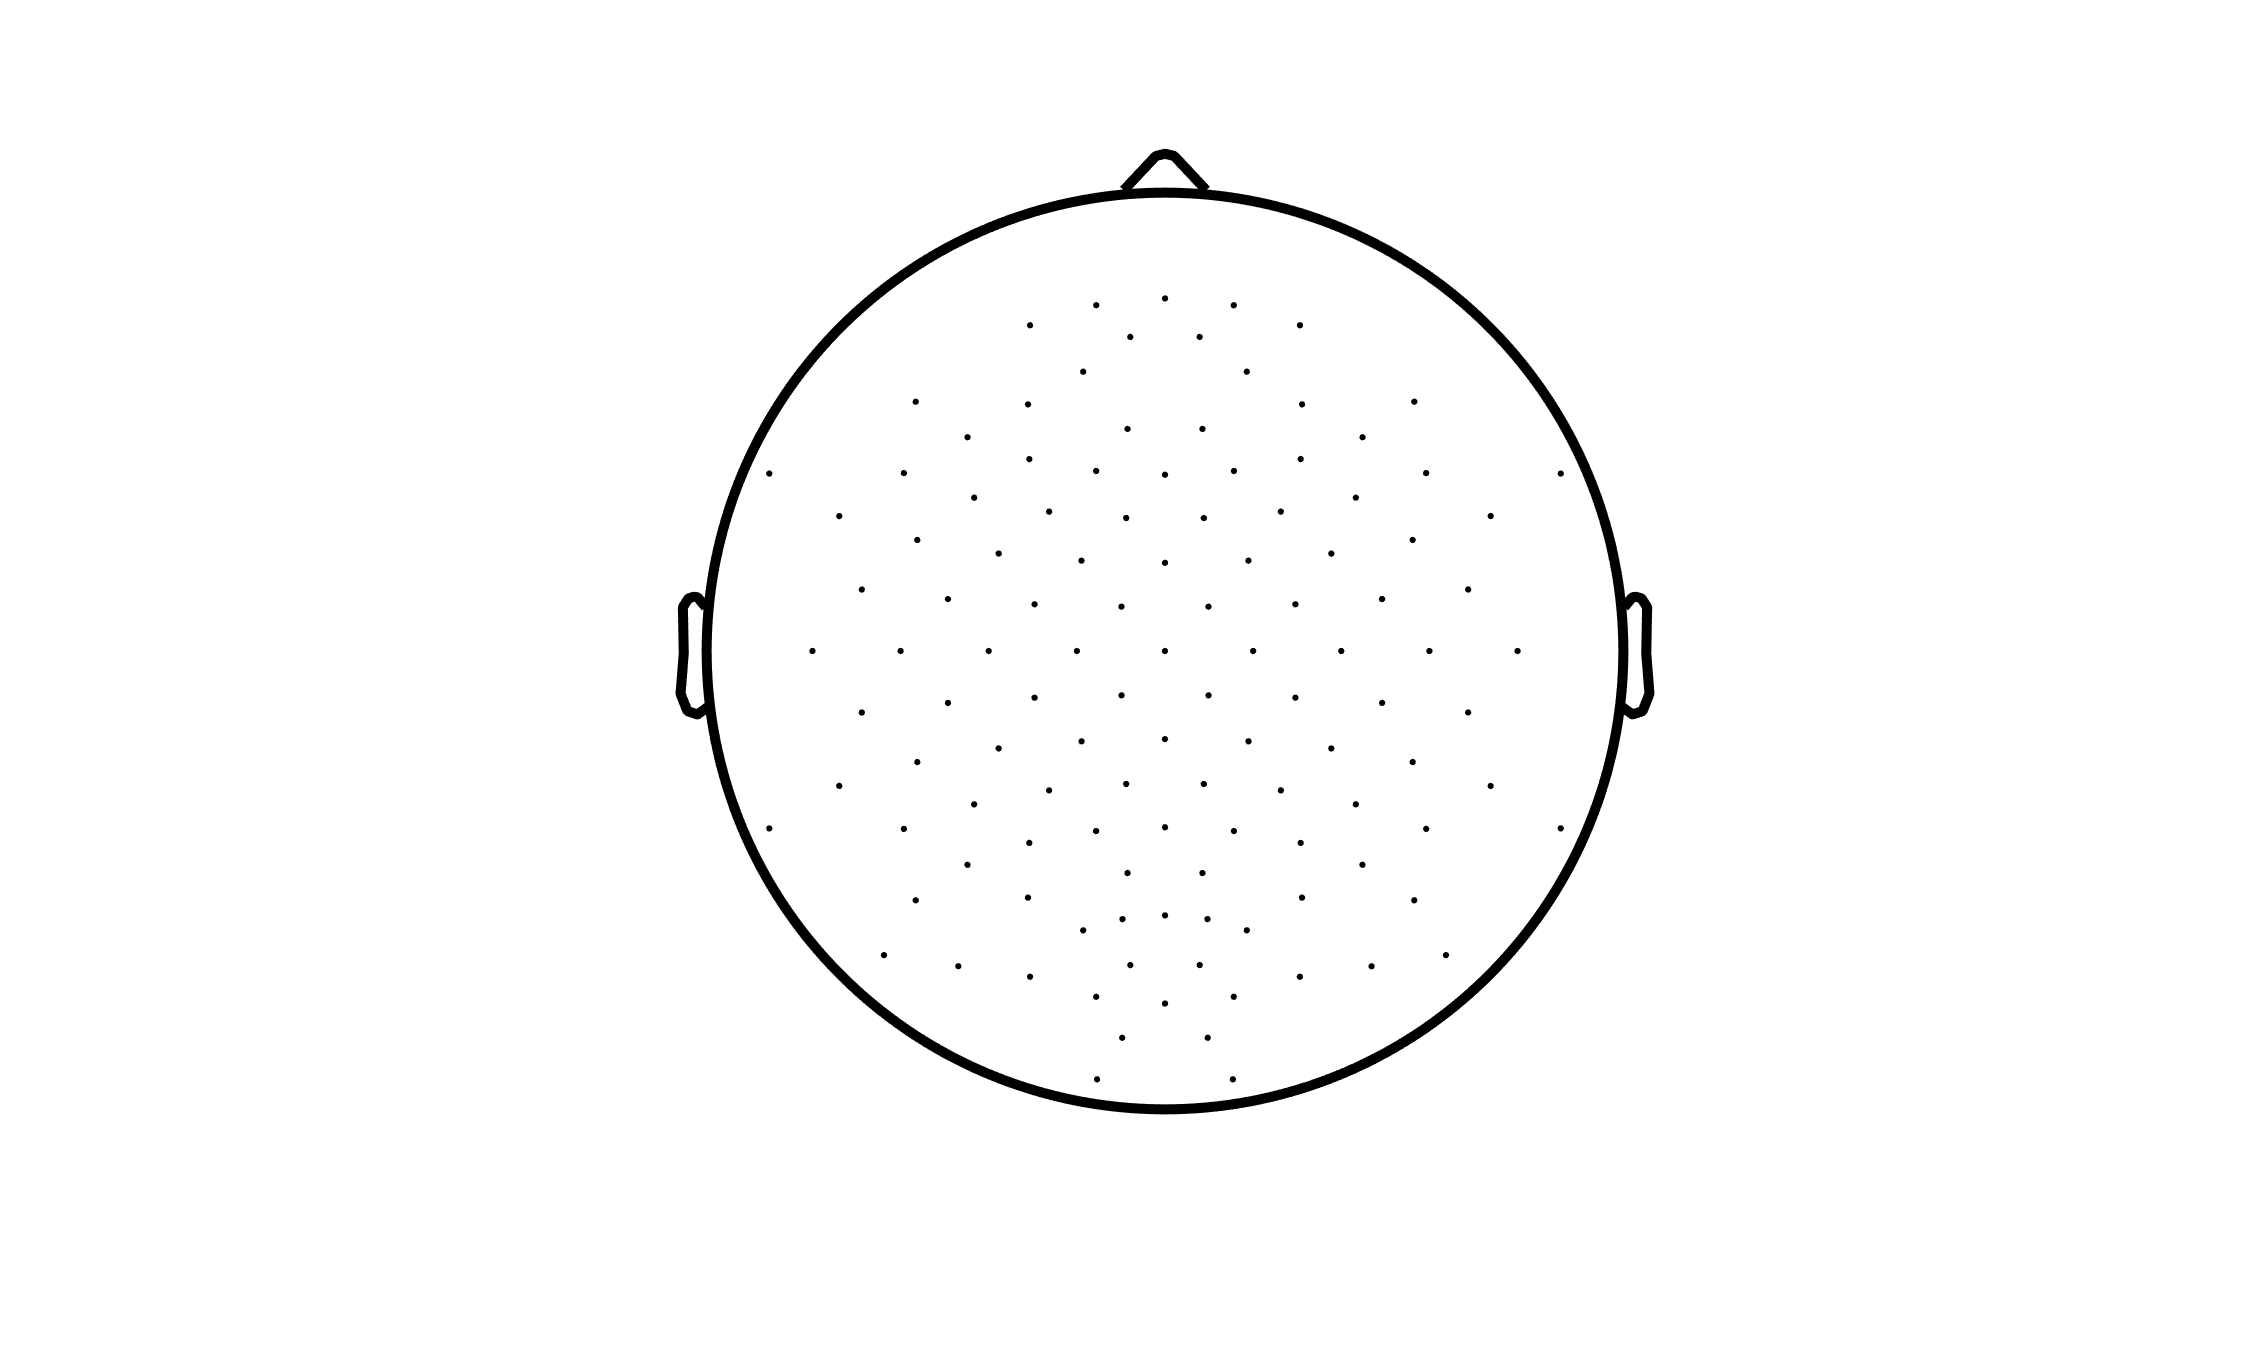

% Load
load('Dataset_IVb.mat');

% Prepare the data to a readable format
Data = 0.1*double(cnt);         %-> Convert raw data to unit of uV
FS = nfo.fs;                    %-> Extract sampling rate : 1000Hz
Time = (0:length(Data)-1) / FS; %-> Prepare a time vector in seconds
clear cnt;                      %-> remove cnt variable to save memory

% Obtain the data labels
Label = zeros(length(Data),1);
for n = 1:length(mrk.pos)
    Label(mrk.pos(n)) = mrk.y(n);
end

% Prepare for the topoplot, for visualization
load('TopoBrainOutline.mat');
t = linspace(0,2*pi,500);
radius = 1;
CircX = radius*cos(t);
CircY = radius*sin(t);
[Xq,Yq] = meshgrid(-1:0.01:1, -1:0.01:1);
Tranparency = ones(size(Xq));
for i = 1:length(Xq)
    CurrentX = Xq(1,i);
    [ClosestX,Index] = min(abs(CurrentX-CircX));
    GetRange = CircY(CircX == CircX(Index));
    if length(GetRange) == 1
        GetRange = [-abs(GetRange) abs(GetRange)];
    end
    ActualSelection = Yq(:,i) < min(GetRange) | Yq(:,i) > max(GetRange);
    Tranparency(ActualSelection,i) = 0;
end

% Show Topoplot
largeFigure(1, [1500 900]); clf; hold on;
scatter3(nfo.xpos, nfo.ypos, ones(size(nfo.xpos))*100, 10, 'k', 'filled');
plot3(CircX, CircY, ones(size(CircY))*100, 'k', 'linewidth', 5);
plot(BrainOutline(6).XData-0.51,BrainOutline(6).YData,'k','linewidth',5)
plot(BrainOutline(7).XData+0.51,BrainOutline(7).YData,'k','linewidth',5)
plot(BrainOutline(8).XData,BrainOutline(8).YData+0.51,'k','linewidth',5)
pbaspect(gca,[1,1,1]); axis([-1.2 1.2 -1.2 1.2]); axis off;

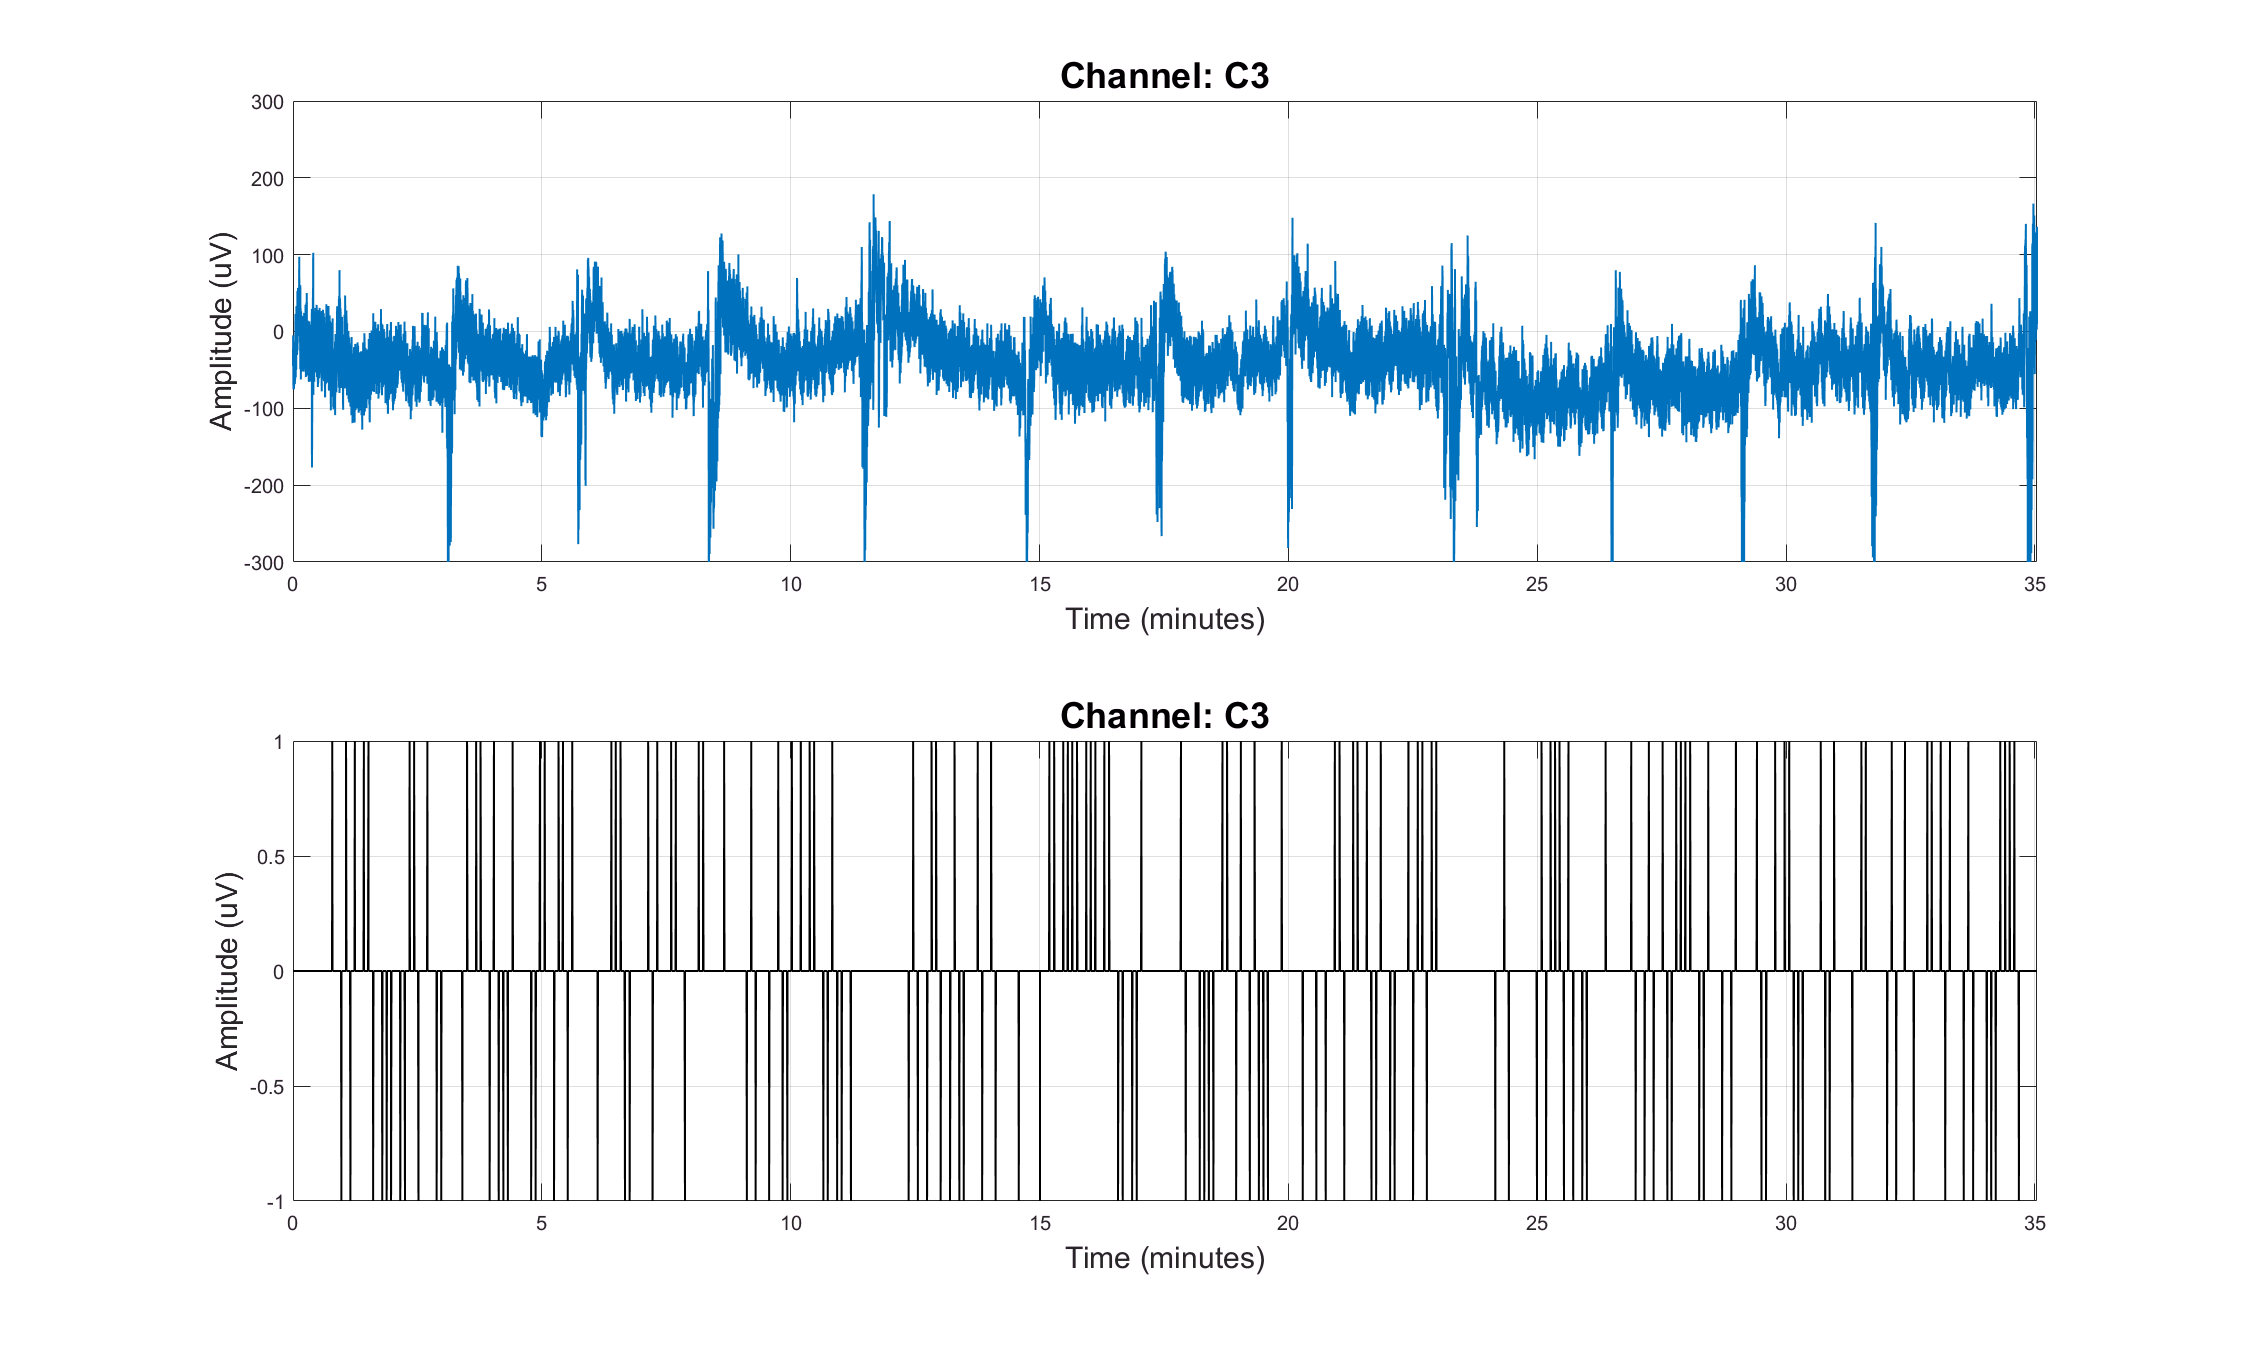

%Visualize the data
channel = 52;
largeFigure(1, [1500 900]); clf;
subplot(2,1,1); cla; hold on; box on; grid on;
plot(Time / 60, Data(:,channel), 'linewidth', 1);
xlim([Time(1) Time(end)]/60);  
ylim([-300 300]);
xlabel('Time (minutes)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

subplot(2,1,2); cla; hold on; box on; grid on;
plot(Time / 60, Label, 'k', 'linewidth', 1);
xlim([Time(1) Time(end)]/60);
xlabel('Time (minutes)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

## Preprocessing Step 1: Common Average Reference (CAR)

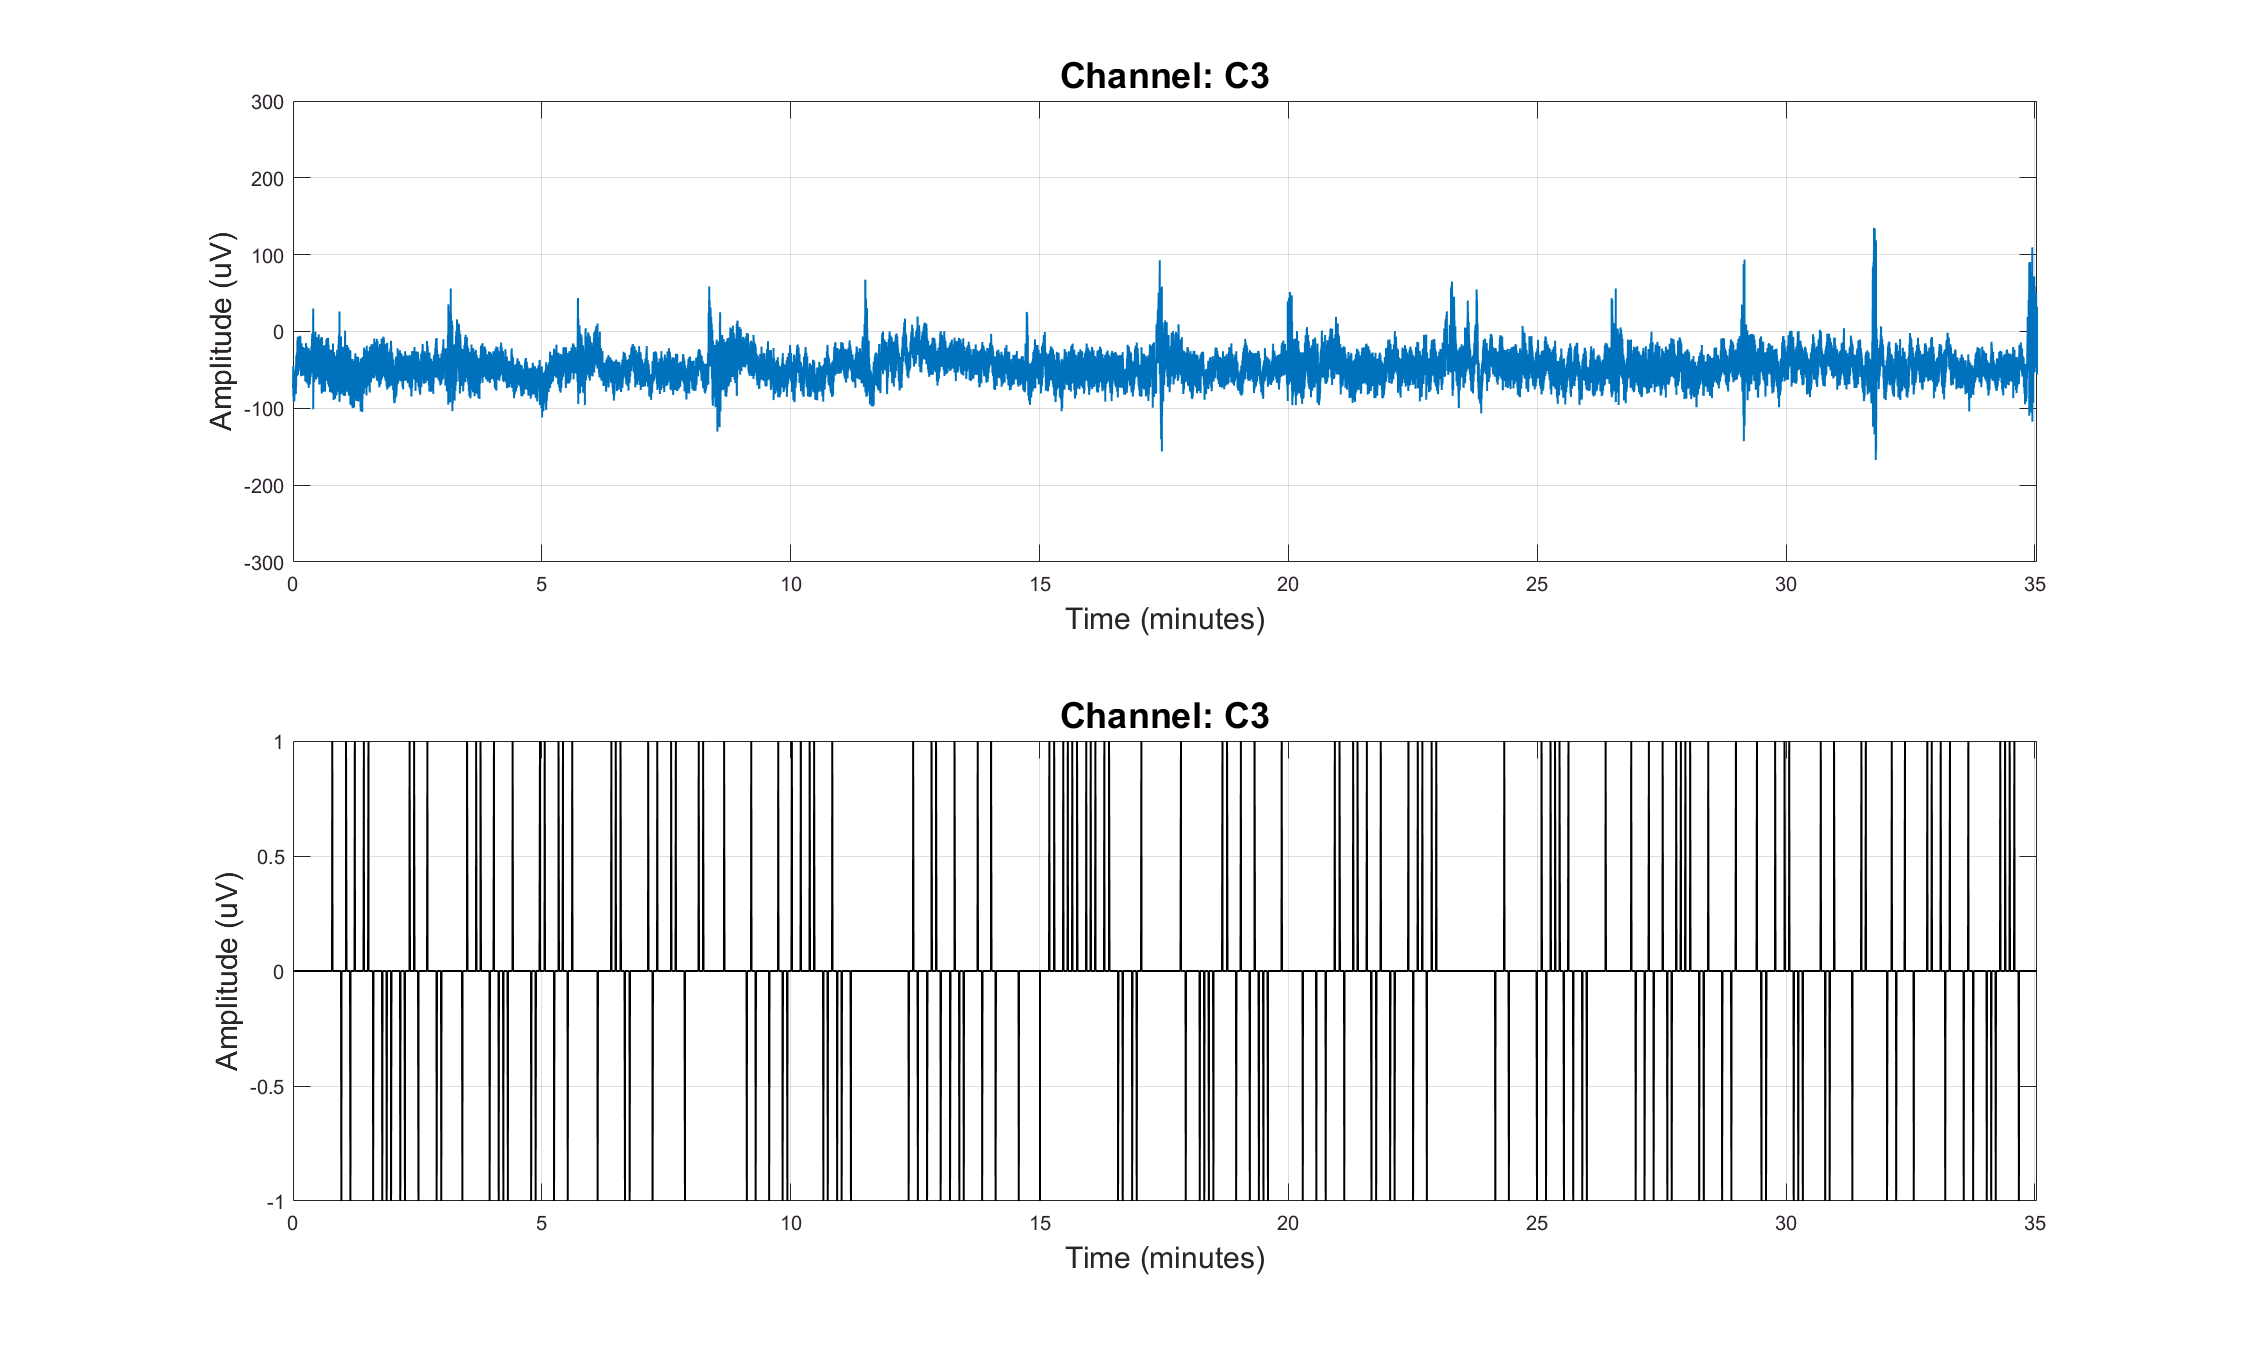

% Element-wise subtraction of average signal from the data
Data = bsxfun(@minus, Data, mean(Data,2));

% Visualize the data again
channel = 52;
largeFigure(1, [1500 900]); clf;
    
subplot(2,1,1); cla; hold on; box on; grid on;
plot(Time / 60, Data(:,channel), 'linewidth', 1);
xlim([Time(1) Time(end)]/60);
ylim([-300 300]);
xlabel('Time (minutes)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

subplot(2,1,2); cla; hold on; box on; grid on;
plot(Time / 60, Label, 'k', 'linewidth', 1);
xlim([Time(1) Time(end)]/60);
xlabel('Time (minutes)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

## Preprocessing Step 2: Digital Filtering

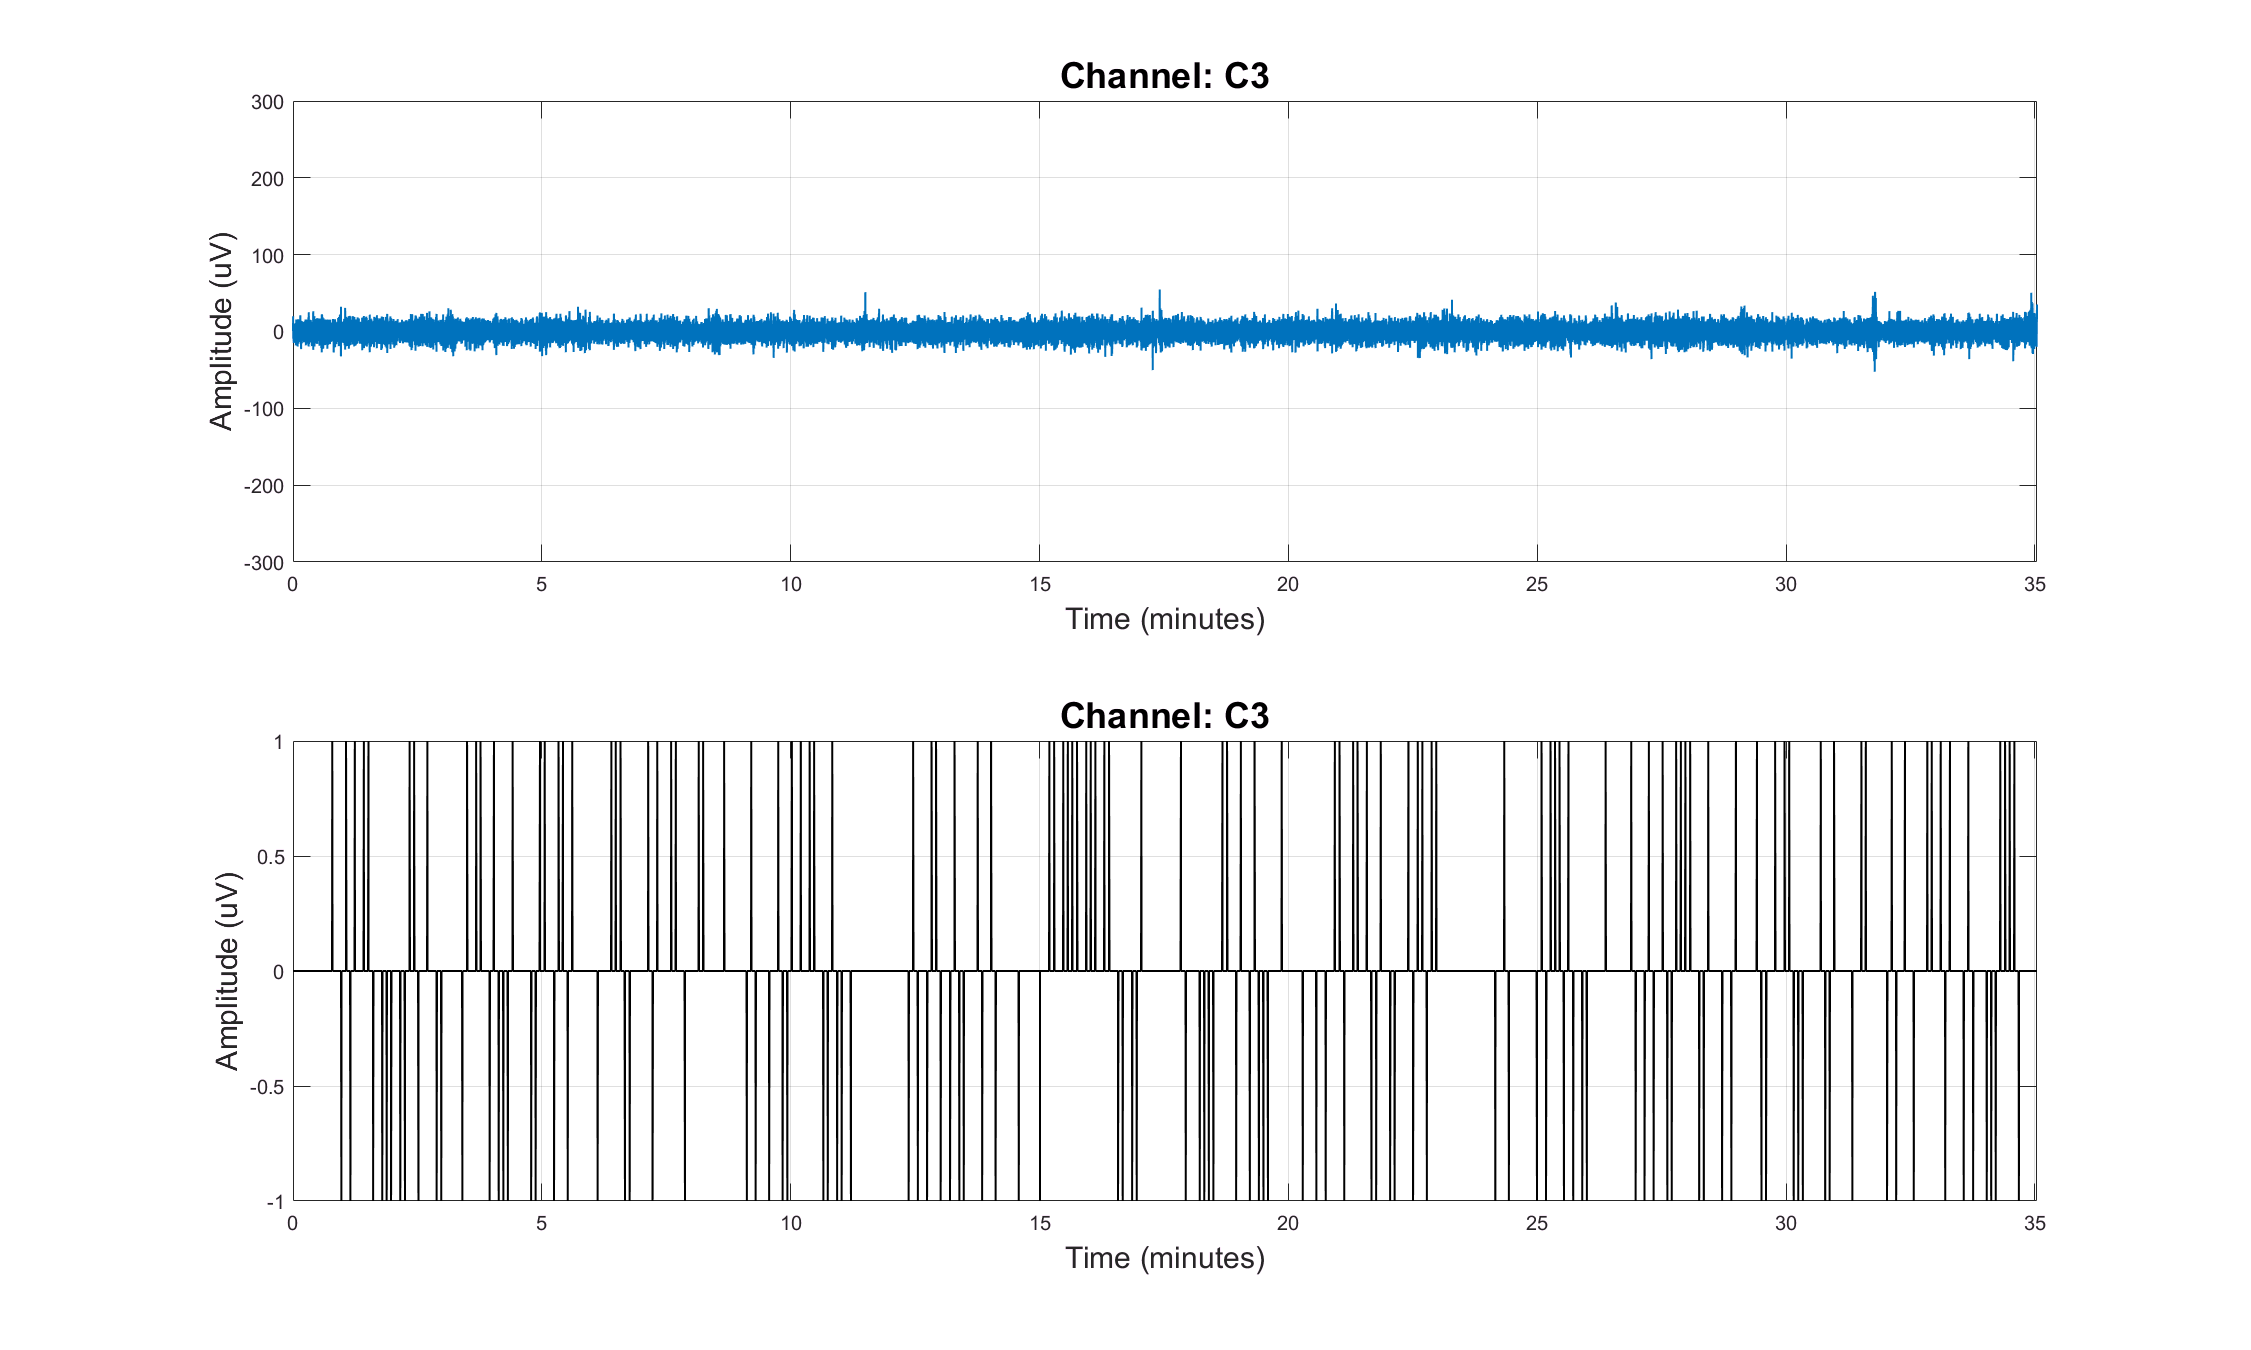

% Setup Infinite-Impulse-Response Filter (Butterworth Filter)
%   Range: 0.5Hz to 50Hz
[b,a] = butter(3, [0.5 50]*2/FS);
Data = filtfilt(b,a,Data);

% Visualize the data again
channel = 52;
largeFigure(1, [1500 900]); clf;

subplot(2,1,1); cla; hold on; box on; grid on;
plot(Time / 60, Data(:,channel), 'linewidth', 1);
xlim([Time(1) Time(end)]/60);
ylim([-300 300]);
xlabel('Time (minutes)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

subplot(2,1,2); cla; hold on; box on; grid on;
plot(Time / 60, Label, 'k', 'linewidth', 1);
xlim([Time(1) Time(end)]/60);
xlabel('Time (minutes)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

## Preprocessing Step 3: Epoching

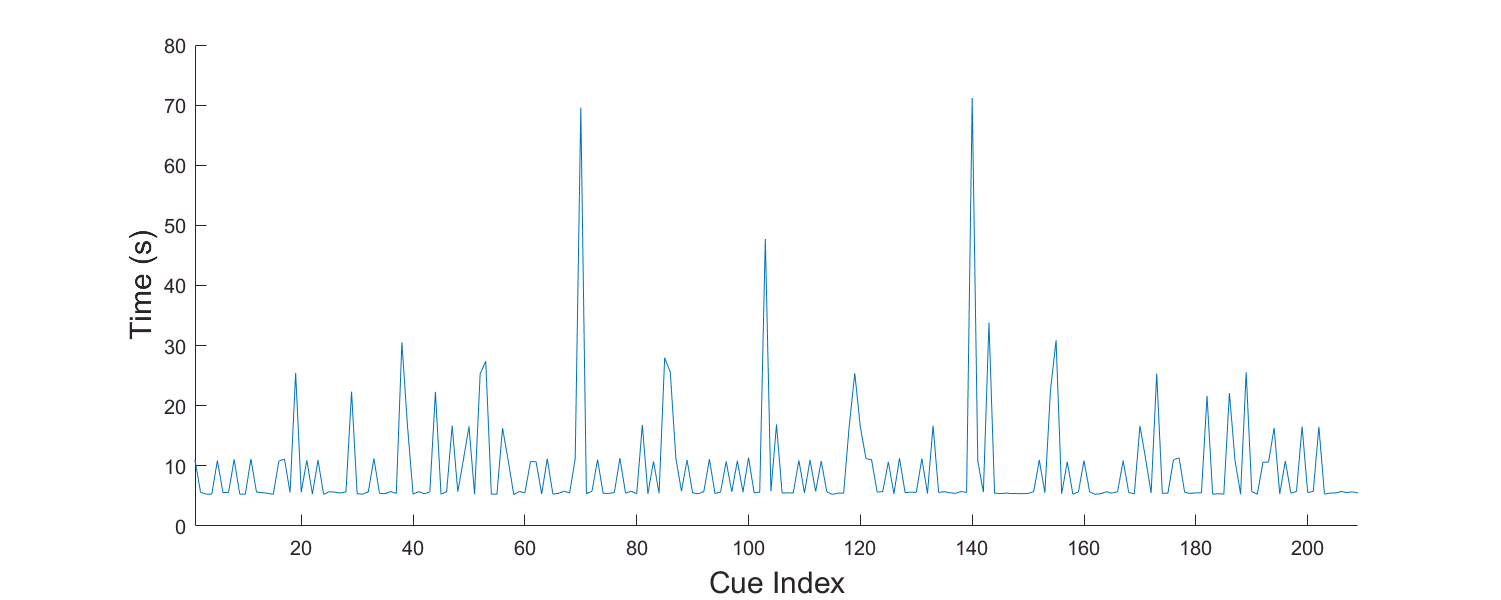

% First, we need to know the task interval to get a good idea abouw how
% much data do we need in each trial
largeFigure(1, [1000 400]); clf; hold on;
plot(diff(mrk.pos) / 1000); 
xlim([1 length(mrk.pos)-1]);
ylabel('Time (s)','fontsize',15);
xlabel('Cue Index','fontsize',15);

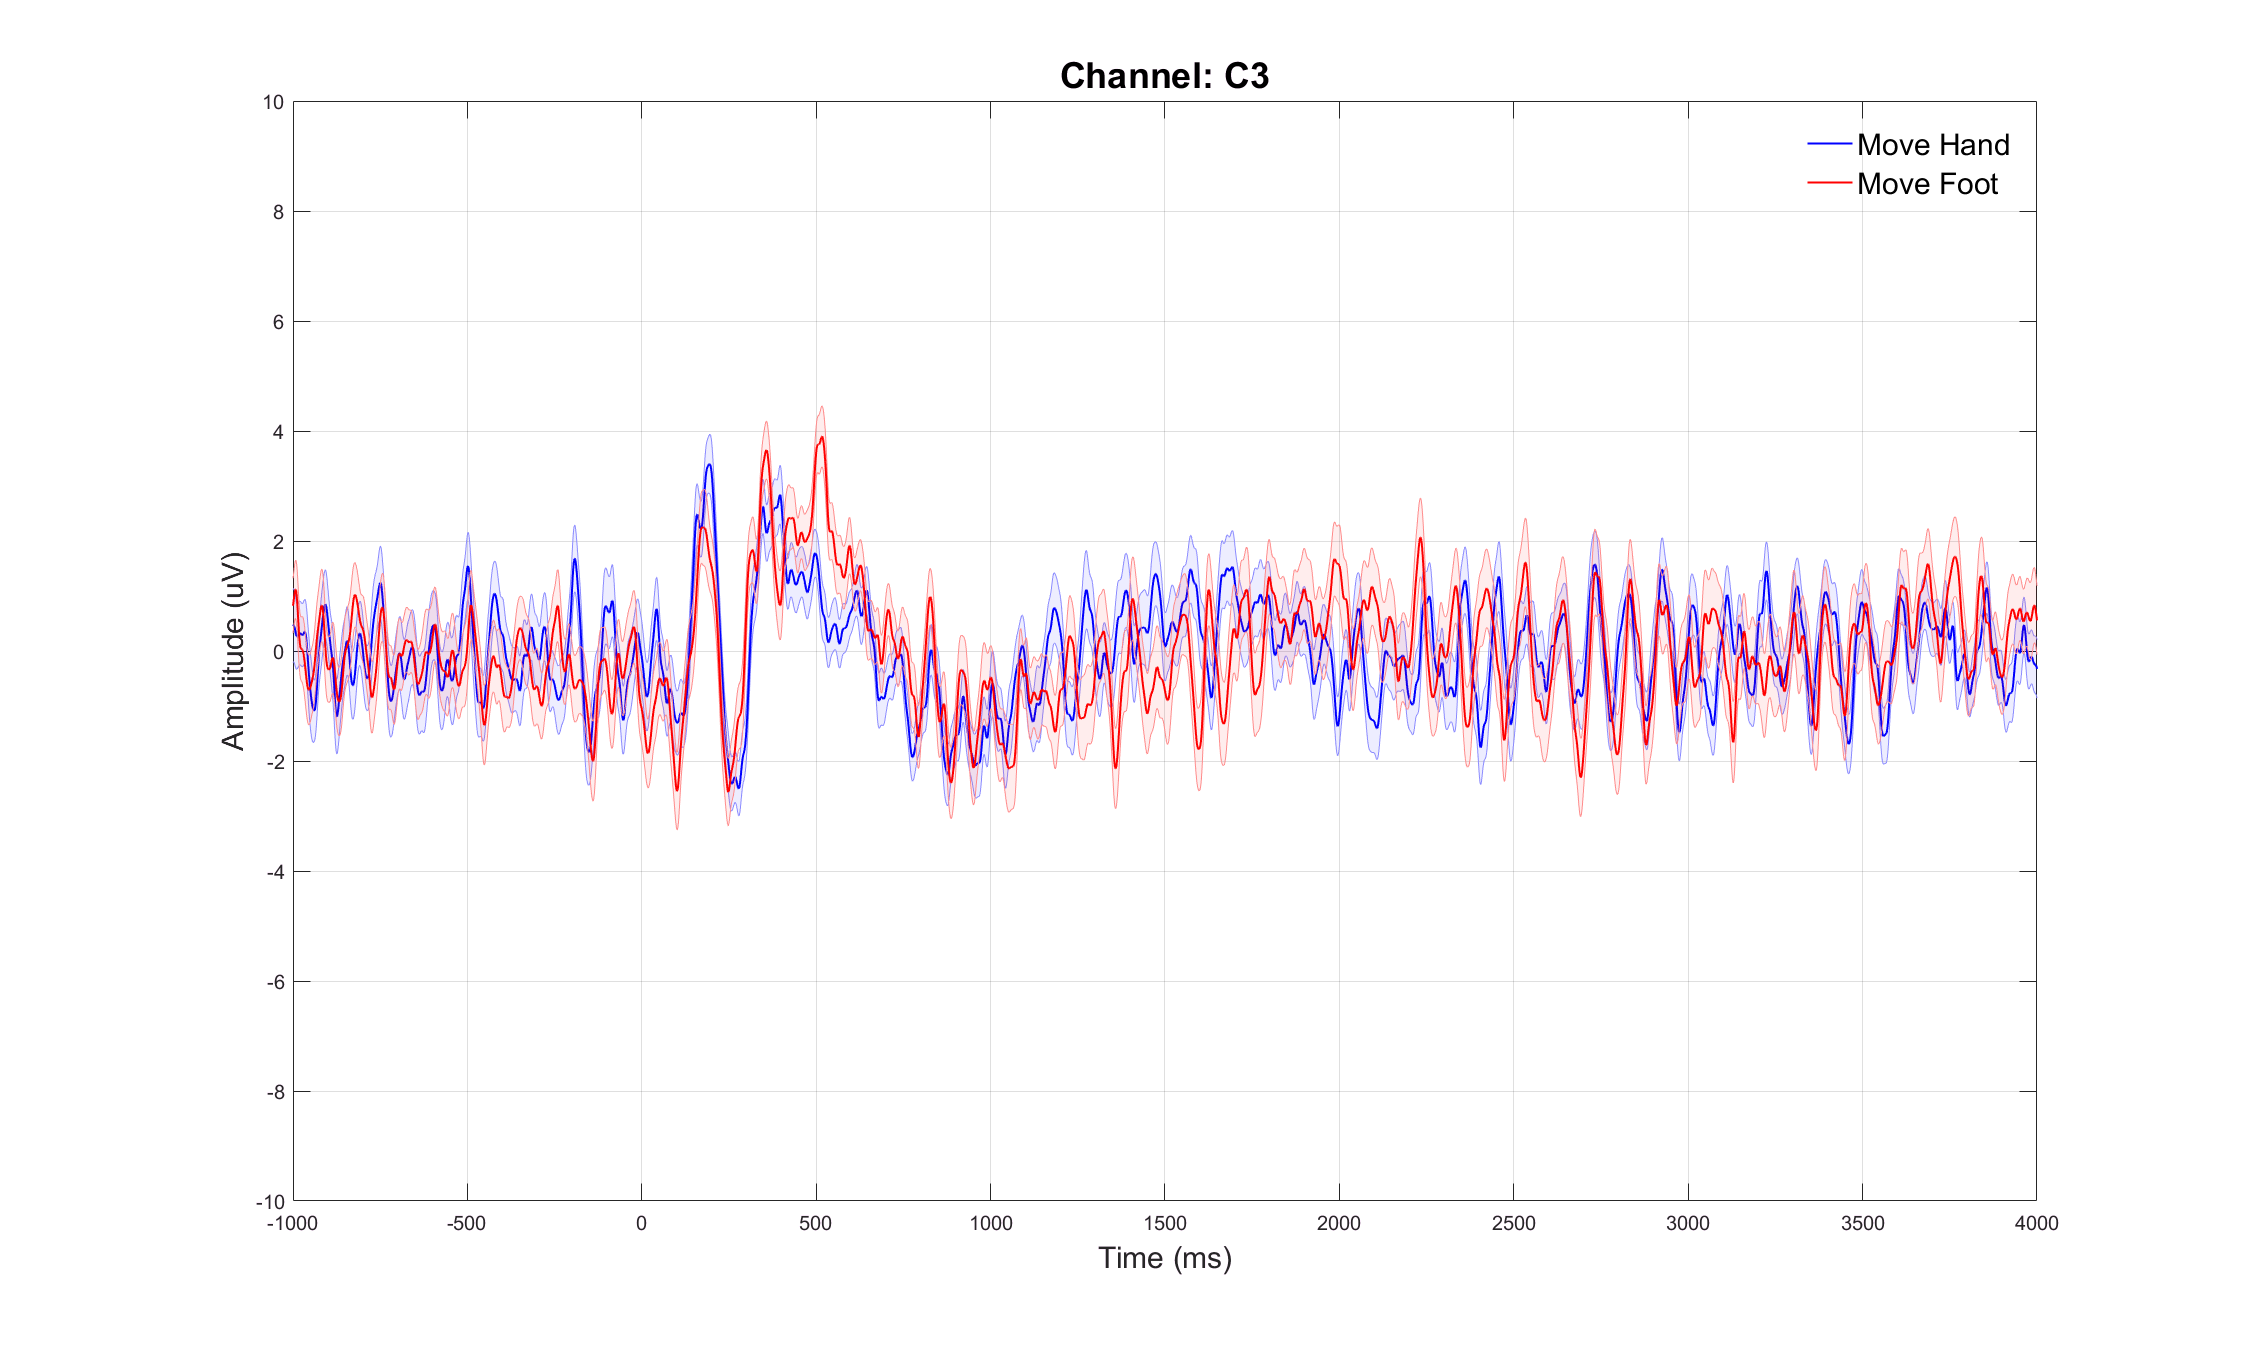


% Epoch them in 5 seconds epoch: 1 second precue, and 4 second post cue
TimeRange = [-1 4];
EpochTime = TimeRange(1)*FS:TimeRange(2)*FS;
HandMovement = zeros(size(Data,2), FS*diff(TimeRange)+1, sum(mrk.y==-1));
FootMovement = zeros(size(Data,2), FS*diff(TimeRange)+1, sum(mrk.y==1));
for n = 1:length(mrk.pos)
    if mrk.y(n) == -1
        TimeSelection = mrk.pos(n)+FS*TimeRange(1):mrk.pos(n)+FS*TimeRange(2);
        HandMovement(:,:,sum(mrk.y(1:n)==-1)) = Data(TimeSelection,:)';
    else
        TimeSelection = mrk.pos(n)+FS*TimeRange(1):mrk.pos(n)+FS*TimeRange(2);
        FootMovement(:,:,sum(mrk.y(1:n)==1)) = Data(TimeSelection,:)';
    end
end

% Let us now visualize our signal as an average of condition
channel = 52;
largeFigure(3, [1500 900]); clf; hold on; box on; grid on;
    
sLine(1) = shadedErrorBar(EpochTime, mean(HandMovement(channel,:,:),3), std(HandMovement(channel,:,:),[],3)/sqrt(size(HandMovement,3)), {'b', 'linewidth', 1}, 0.5);
xlim([EpochTime(1) EpochTime(end)]);
ylim([-10 10]);
xlabel('Time (ms)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

sLine(2) = shadedErrorBar(EpochTime, mean(FootMovement(channel,:,:),3), std(FootMovement(channel,:,:),[],3)/sqrt(size(FootMovement,3)), {'r', 'linewidth', 1}, 0.5);
xlim([EpochTime(1) EpochTime(end)]);
ylim([-10 10]);
xlabel('Time (ms)', 'fontsize', 15);
ylabel('Amplitude (uV)', 'fontsize', 15);
title(sprintf('Channel: %s',nfo.clab{channel}),'fontsize',18);

legendFont([sLine(1).mainLine,sLine(2).mainLine], {'Move Hand', 'Move Foot'}, {'fontsize',15});

## Preprocessing Step 4: Independent Component Analysis - based on EEGLAB

% This dataset actually does not benefit too much from ICA, but I will
% still put the code here if you want to run them. You must have EEGLAB
% toolbox from https://sccn.ucsd.edu/eeglab/index.php
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;
EEG = pop_importdata('dataformat','array','nbchan',118,'data','HandMovement','setname','BCI_Dataset','srate',1000,'subject','Anonymous','pnts',size(HandMovement,2),'condition','Motor Imagery','xmin',-1000,'session',[],'chanlocs','C:\\Users\\jcagle\\Documents\\Datasets\\BCI Competition III\\channel.xyz');
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 
EEG = pop_runica(EEG, 'extended',1,'pca',50,'interupt','on');
[ALLEEG EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
EEG = eeg_checkset( EEG );
eeglab redraw;

## Feature Extraction - Spectral Features

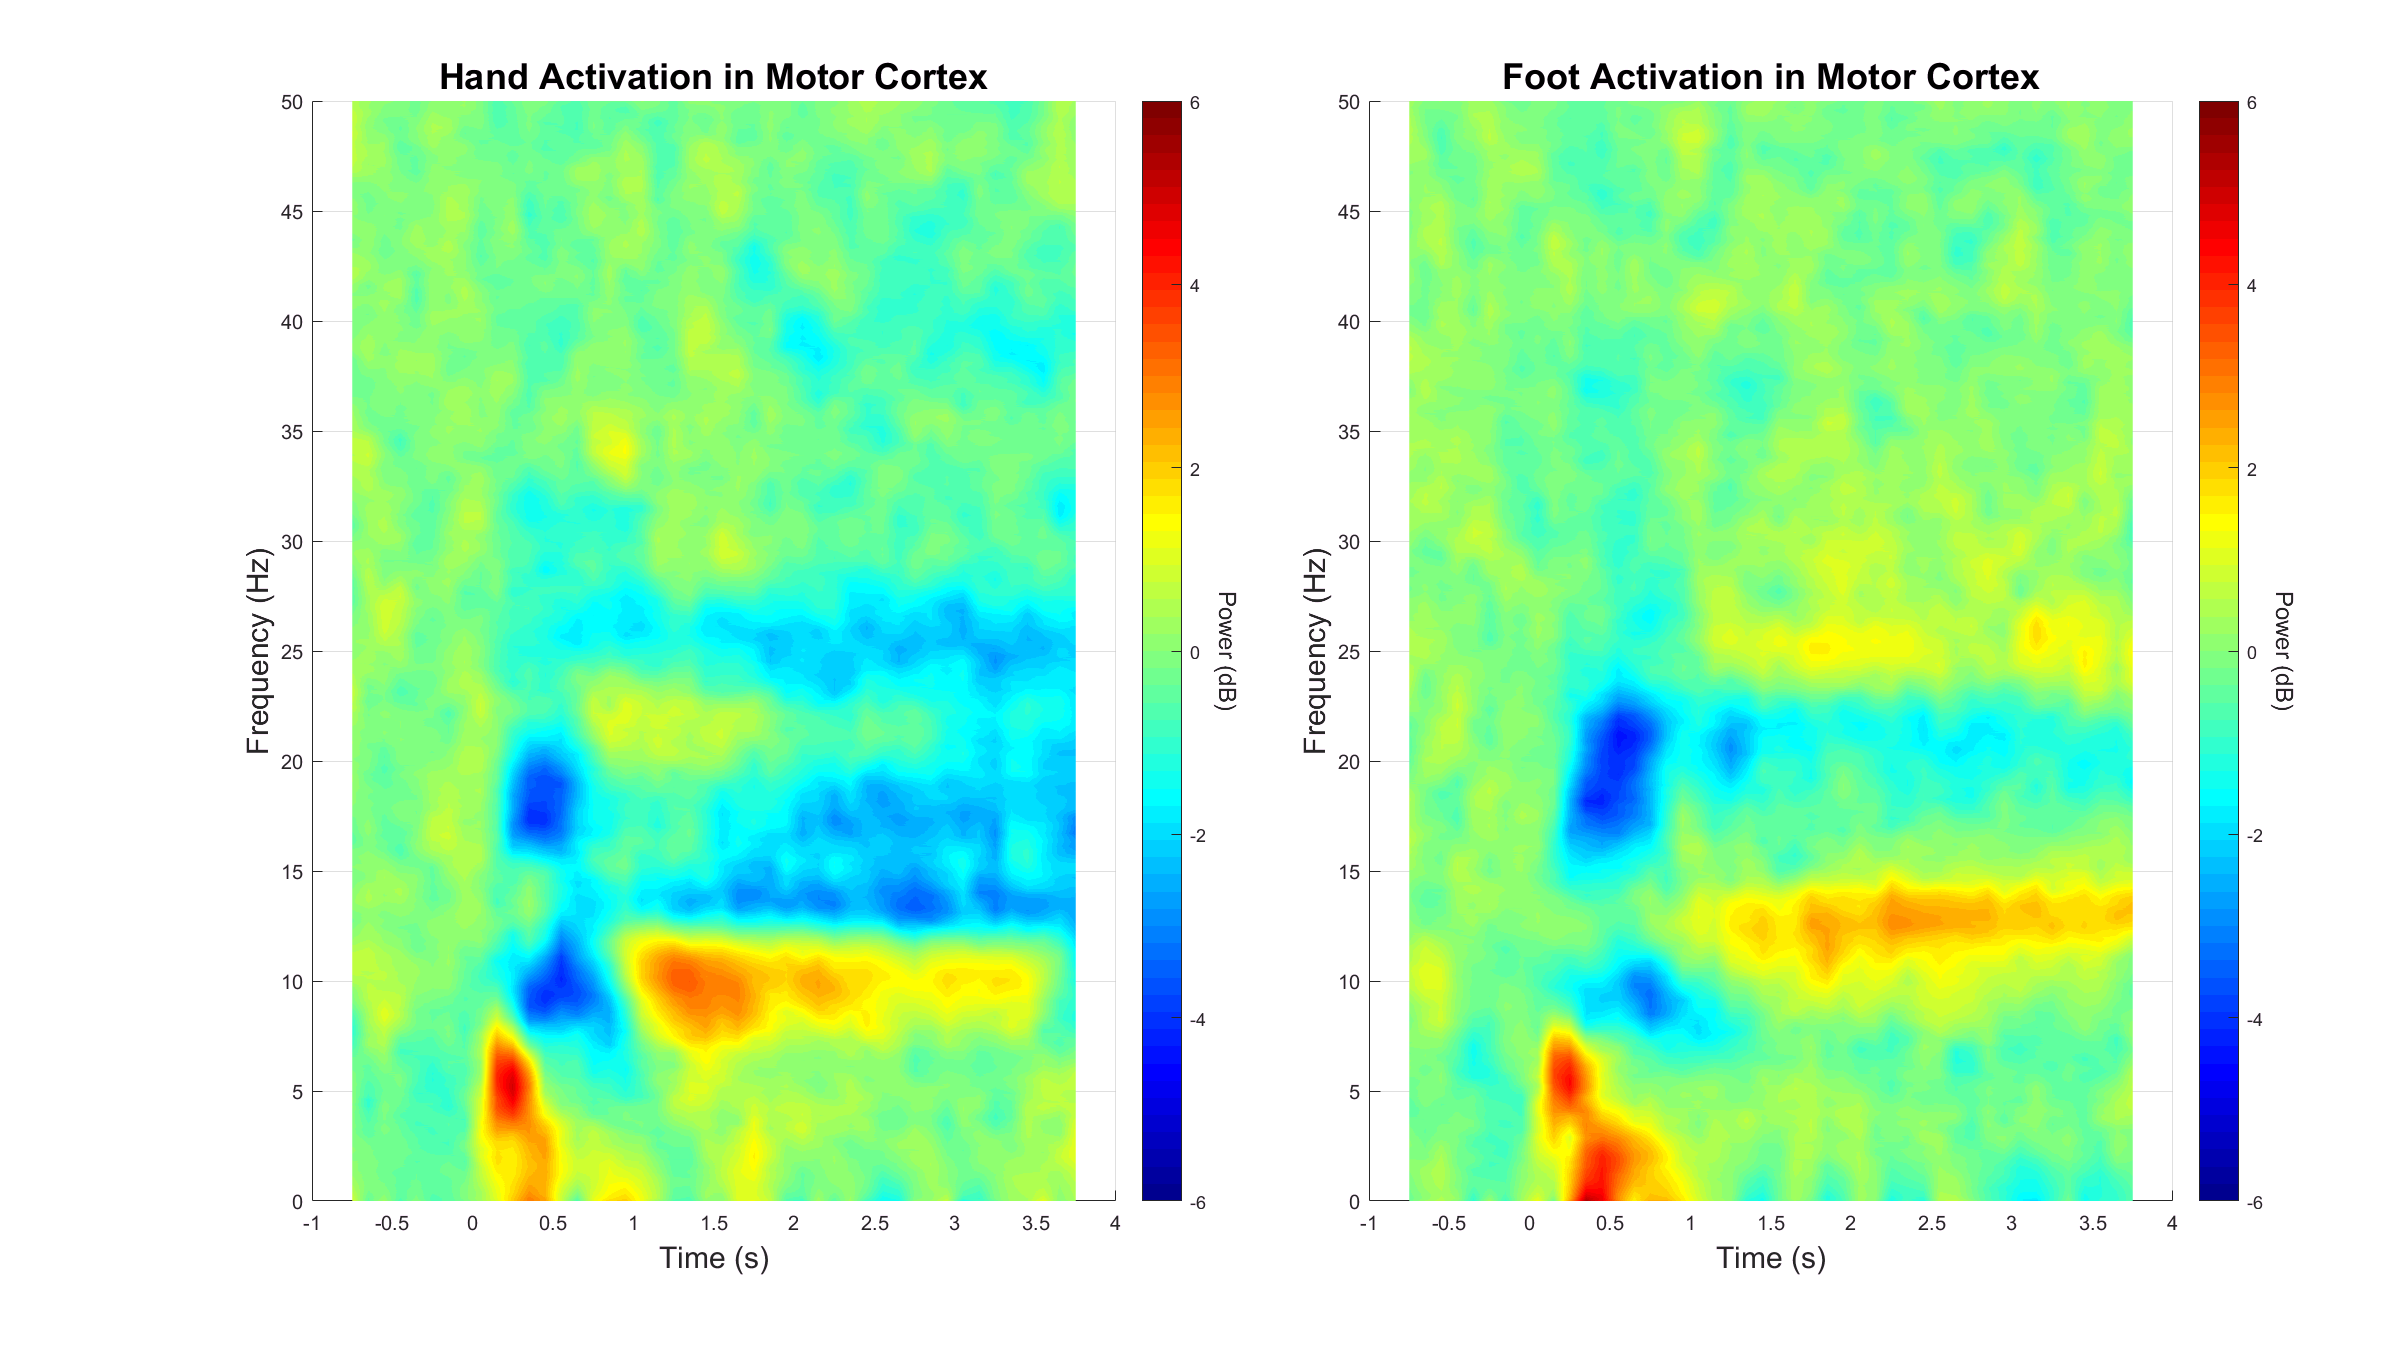

% Time-Frequency Analysis
MotorChannel = [52 54 56];               % C3 Cz C4
Frequency = 0:0.1:50;
Window = 500;
Overlap = 400;
T = getIndices(size(HandMovement,2), Window, Overlap, 'floor');
TimeSelection = T/FS + TimeRange(1) < 0;

% Normalize to baseline (Prior to onset)

HandSpectrum = zeros(size(HandMovement,1), length(Frequency), length(T), size(HandMovement,3));
for channel = 1:size(HandMovement,1)
    for trial = 1:size(HandMovement,3)
        [~,~,SpectrumTime,P] = spectrogram(mean(HandMovement(channel,:,trial),1), Window, Overlap, Frequency, FS);
        HandSpectrum(channel,:,:,trial) = 10*log10(P);
        HandSpectrum(channel,:,:,trial) = bsxfun(@minus, HandSpectrum(channel,:,:,trial), mean(HandSpectrum(channel,:,TimeSelection,trial),3)); % Normalize to baseline (Prior to onset)
    end
end

FootSpectrum = zeros(size(FootMovement,1), length(Frequency), length(T), size(FootMovement,3));
for channel = 1:size(FootMovement,1)
    for trial = 1:size(FootMovement,3)
        [~,~,SpectrumTime,P] = spectrogram(mean(FootMovement(channel,:,trial),1), Window, Overlap, Frequency, FS);
        FootSpectrum(channel,:,:,trial) = 10*log10(P);
        FootSpectrum(channel,:,:,trial) = bsxfun(@minus, FootSpectrum(channel,:,:,trial), mean(FootSpectrum(channel,:,TimeSelection,trial),3)); % Normalize to baseline (Prior to onset)
    end
end

% Visualize the Time-Frequency Analysis
largeFigure(4, [1600 900]); clf; colormap jet;
subplot(1,2,1); cla; box on; grid on;
surf(SpectrumTime+TimeRange(1), Frequency, squeeze(mean(mean(HandSpectrum(MotorChannel,:,:,:),4),1))); view(2); shading interp;
caxis([-6 6]);
addColorbar('Power (dB)');
xlabel('Time (s)', 'fontsize', 15);
ylabel('Frequency (Hz)', 'fontsize', 15);
title('Hand Activation in Motor Cortex','fontsize',18);

subplot(1,2,2); cla; box on; grid on;
surf(SpectrumTime+TimeRange(1), Frequency, squeeze(mean(mean(FootSpectrum(MotorChannel,:,:,:),4),1))); view(2); shading interp;
caxis([-6 6]);
addColorbar('Power (dB)');
xlabel('Time (s)', 'fontsize', 15);
ylabel('Frequency (Hz)', 'fontsize', 15);
title('Foot Activation in Motor Cortex','fontsize',18);

## Feature Extraction - How about the well-known frequency bands?

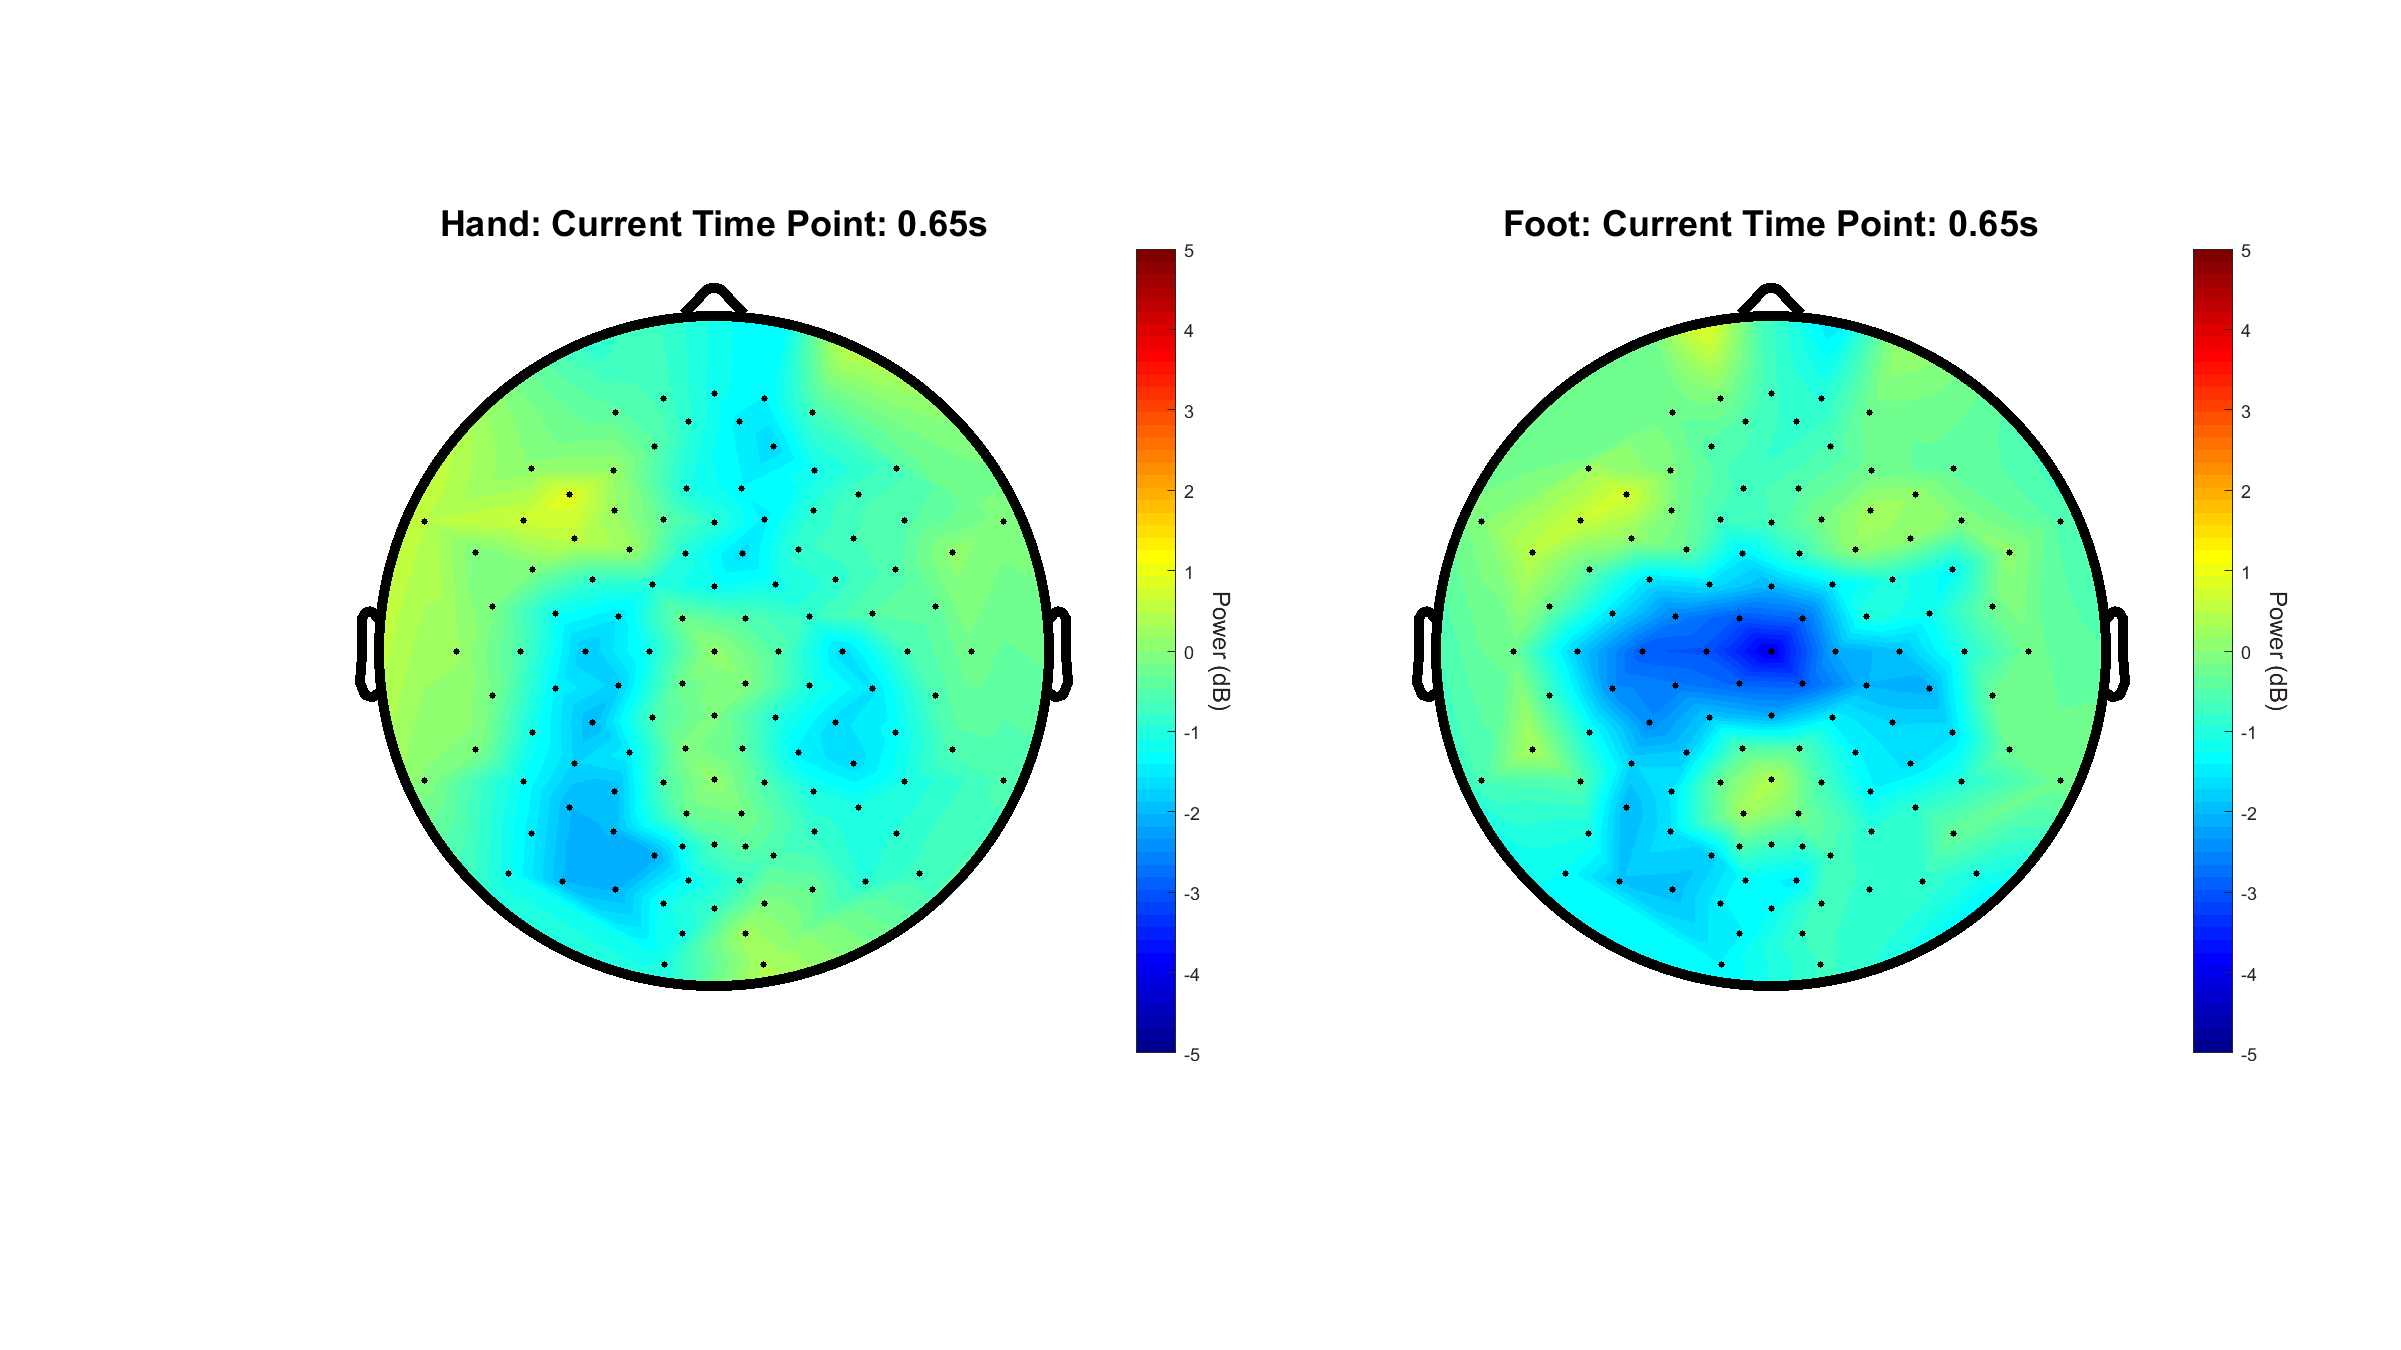

% Select Frequency Band
FrequencySelection = Frequency > 18 & Frequency < 25;
TopoAlphaHand = zeros(size(HandSpectrum,1), length(SpectrumTime));
TopoAlphaFoot = zeros(size(FootSpectrum,1), length(SpectrumTime));
for channel = 1:size(HandSpectrum,1)
    TopoAlphaHand(channel,:) = mean(mean(HandSpectrum(channel,FrequencySelection,:,:),2),4);
    TopoAlphaFoot(channel,:) = mean(mean(FootSpectrum(channel,FrequencySelection,:,:),2),4);
end

largeFigure(4, [1600 900]); clf; 
T = 15;
subplot(1,2,1); cla; hold on; colormap jet;
F = scatteredInterpolant(nfo.xpos, nfo.ypos, TopoAlphaHand(:,T));
Vq = F(Xq,Yq);
surf(Xq, Yq, Vq, 'FaceColor','interp','AlphaData', Tranparency, 'FaceAlpha', 'interp'); shading interp; view(2); axis off;  axis([-1.2 1.2 -1.2 1.2]);
pbaspect(gca,[1,1,1]); addColorbar('Power (dB)'); caxis([-5 5]);
scatter3(nfo.xpos, nfo.ypos, ones(size(nfo.xpos))*100, 10, 'k', 'filled');
plot3(CircX, CircY, ones(size(CircY))*100, 'k', 'linewidth', 5);
plot(BrainOutline(6).XData-0.51,BrainOutline(6).YData,'k','linewidth',5)
plot(BrainOutline(7).XData+0.51,BrainOutline(7).YData,'k','linewidth',5)
plot(BrainOutline(8).XData,BrainOutline(8).YData+0.51,'k','linewidth',5)
title(sprintf('Hand: Current Time Point: %.2fs',SpectrumTime(T)+TimeRange(1)), 'fontsize', 18);

subplot(1,2,2); cla; hold on; colormap jet;
F = scatteredInterpolant(nfo.xpos, nfo.ypos, TopoAlphaFoot(:,T));
Vq = F(Xq,Yq);
surf(Xq, Yq, Vq, 'FaceColor','interp','AlphaData', Tranparency, 'FaceAlpha', 'interp'); shading interp; view(2); axis off;  axis([-1.2 1.2 -1.2 1.2]);
pbaspect(gca,[1,1,1]); addColorbar('Power (dB)'); caxis([-5 5]);
scatter3(nfo.xpos, nfo.ypos, ones(size(nfo.xpos))*100, 10, 'k', 'filled');
plot3(CircX, CircY, ones(size(CircY))*100, 'k', 'linewidth', 5);
plot(BrainOutline(6).XData-0.51,BrainOutline(6).YData,'k','linewidth',5)
plot(BrainOutline(7).XData+0.51,BrainOutline(7).YData,'k','linewidth',5)
plot(BrainOutline(8).XData,BrainOutline(8).YData+0.51,'k','linewidth',5)
title(sprintf('Foot: Current Time Point: %.2fs',SpectrumTime(T)+TimeRange(1)), 'fontsize', 18);

## Machine Learning - Feature Selection / Feature Ranking

% Construct Feature Vectors and Label Vector
FeatureVector = zeros(size(HandSpectrum,4)+size(FootSpectrum,4),size(HandSpectrum,1)*size(HandSpectrum,2)*size(HandSpectrum,3));
Label = zeros(size(HandSpectrum,4)+size(FootSpectrum,4),1);
count = 1;
for trials = 1:size(HandSpectrum,4)
    FeatureVector(count,:) = reshape(HandSpectrum(:,:,:,trials),[1,size(HandSpectrum,1)*size(HandSpectrum,2)*size(HandSpectrum,3)]);
    Label(count) = 1;
    count = count + 1;
end
for trials = 1:size(FootSpectrum,4)
    FeatureVector(count,:) = reshape(FootSpectrum(:,:,:,trials),[1,size(FootSpectrum,1)*size(FootSpectrum,2)*size(FootSpectrum,3)]);
    Label(count) = 0;
    count = count + 1;
end
clear HandSpectrum FootSpectrum;

% Split Data into Training and Testing
Instances = randperm(length(Label));
TestingIndex = Instances(1:round(length(Label)*0.2));
TrainingIndex = Instances(round(length(Label)*0.2)+1:end);
Feature_train = FeatureVector(TrainingIndex,:);
Label_train = Label(TrainingIndex,:);
Feature_test = FeatureVector(TestingIndex,:);
Label_test = Label(TestingIndex,:);
clear FeatureVector Label;

% "Preprocess" the data again
mu = mean(Feature_train,1);
sigma = std(Feature_train,[],1);
Feature_train = (Feature_train - repmat(mu,[size(Feature_train,1),1])) ./ repmat(sigma,[size(Feature_train,1),1]);
Feature_test = (Feature_test - repmat(mu,[size(Feature_test,1),1])) ./ repmat(sigma,[size(Feature_test,1),1]);
clear mu sigma;

% Rank the feature based on maximum separation
Significance = zeros(1,size(Feature_train,2));
for n = 1:size(Feature_train,2)
    [~,Significance(n)] = corr(Feature_train(:,n),Label_train);
end
[~,FeatureRanking] = sort(Significance);

## Machine Learning - Feature Ranking compares to Physiology Pt.1: Cross-Validation

% OK, time to build a simple linear Support Vector Machine
%   This is based on LIBSVM from https://www.csie.ntu.edu.tw/~cjlin/libsvm/
FeatureLevel = round(logspace(1,5,100));
ValidationAccuracy = zeros(size(FeatureLevel));
for n = 1:length(FeatureLevel)
    SelectedFeature = FeatureRanking(1:FeatureLevel(n));
    ValidationAccuracy(n) = svmtrain(Label_train, Feature_train(:,SelectedFeature), '-s 0 -t 0 -h 0 -v 10 -q');
end

Cross Validation Accuracy = 82.7381%
Cross Validation Accuracy = 83.3333%
Cross Validation Accuracy = 83.3333%
Cross Validation Accuracy = 83.3333%
Cross Validation Accuracy = 84.5238%
Cross Validation Accuracy = 84.5238%
Cross Validation Accuracy = 84.5238%
Cross Validation Accuracy = 84.5238%
Cross Validation Accuracy = 83.9286%
Cross Validation Accuracy = 84.5238%
Cross Validation Accuracy = 83.9286%
Cross Validation Accuracy = 82.7381%
Cross Validation Accuracy = 82.1429%
Cross Validation Accuracy = 83.3333%
Cross Validation Accuracy = 82.1429%
Cross Validation Accuracy = 81.5476%
Cross Validation Accuracy = 82.1429%
Cross Validation Accuracy = 80.3571%
Cross Validation Accuracy = 79.7619%
Cross Validation Accuracy = 80.3571%
Cross Validation Accuracy = 80.9524%
Cross Validation Accuracy = 80.9524%
Cross Validation Accuracy = 79.7619%
Cross Validation Accuracy = 79.7619%
Cross Validation Accuracy = 77.381%
Cross Validation Accuracy = 79.7619%
Cross Validation Accuracy = 79.1667%
Cr

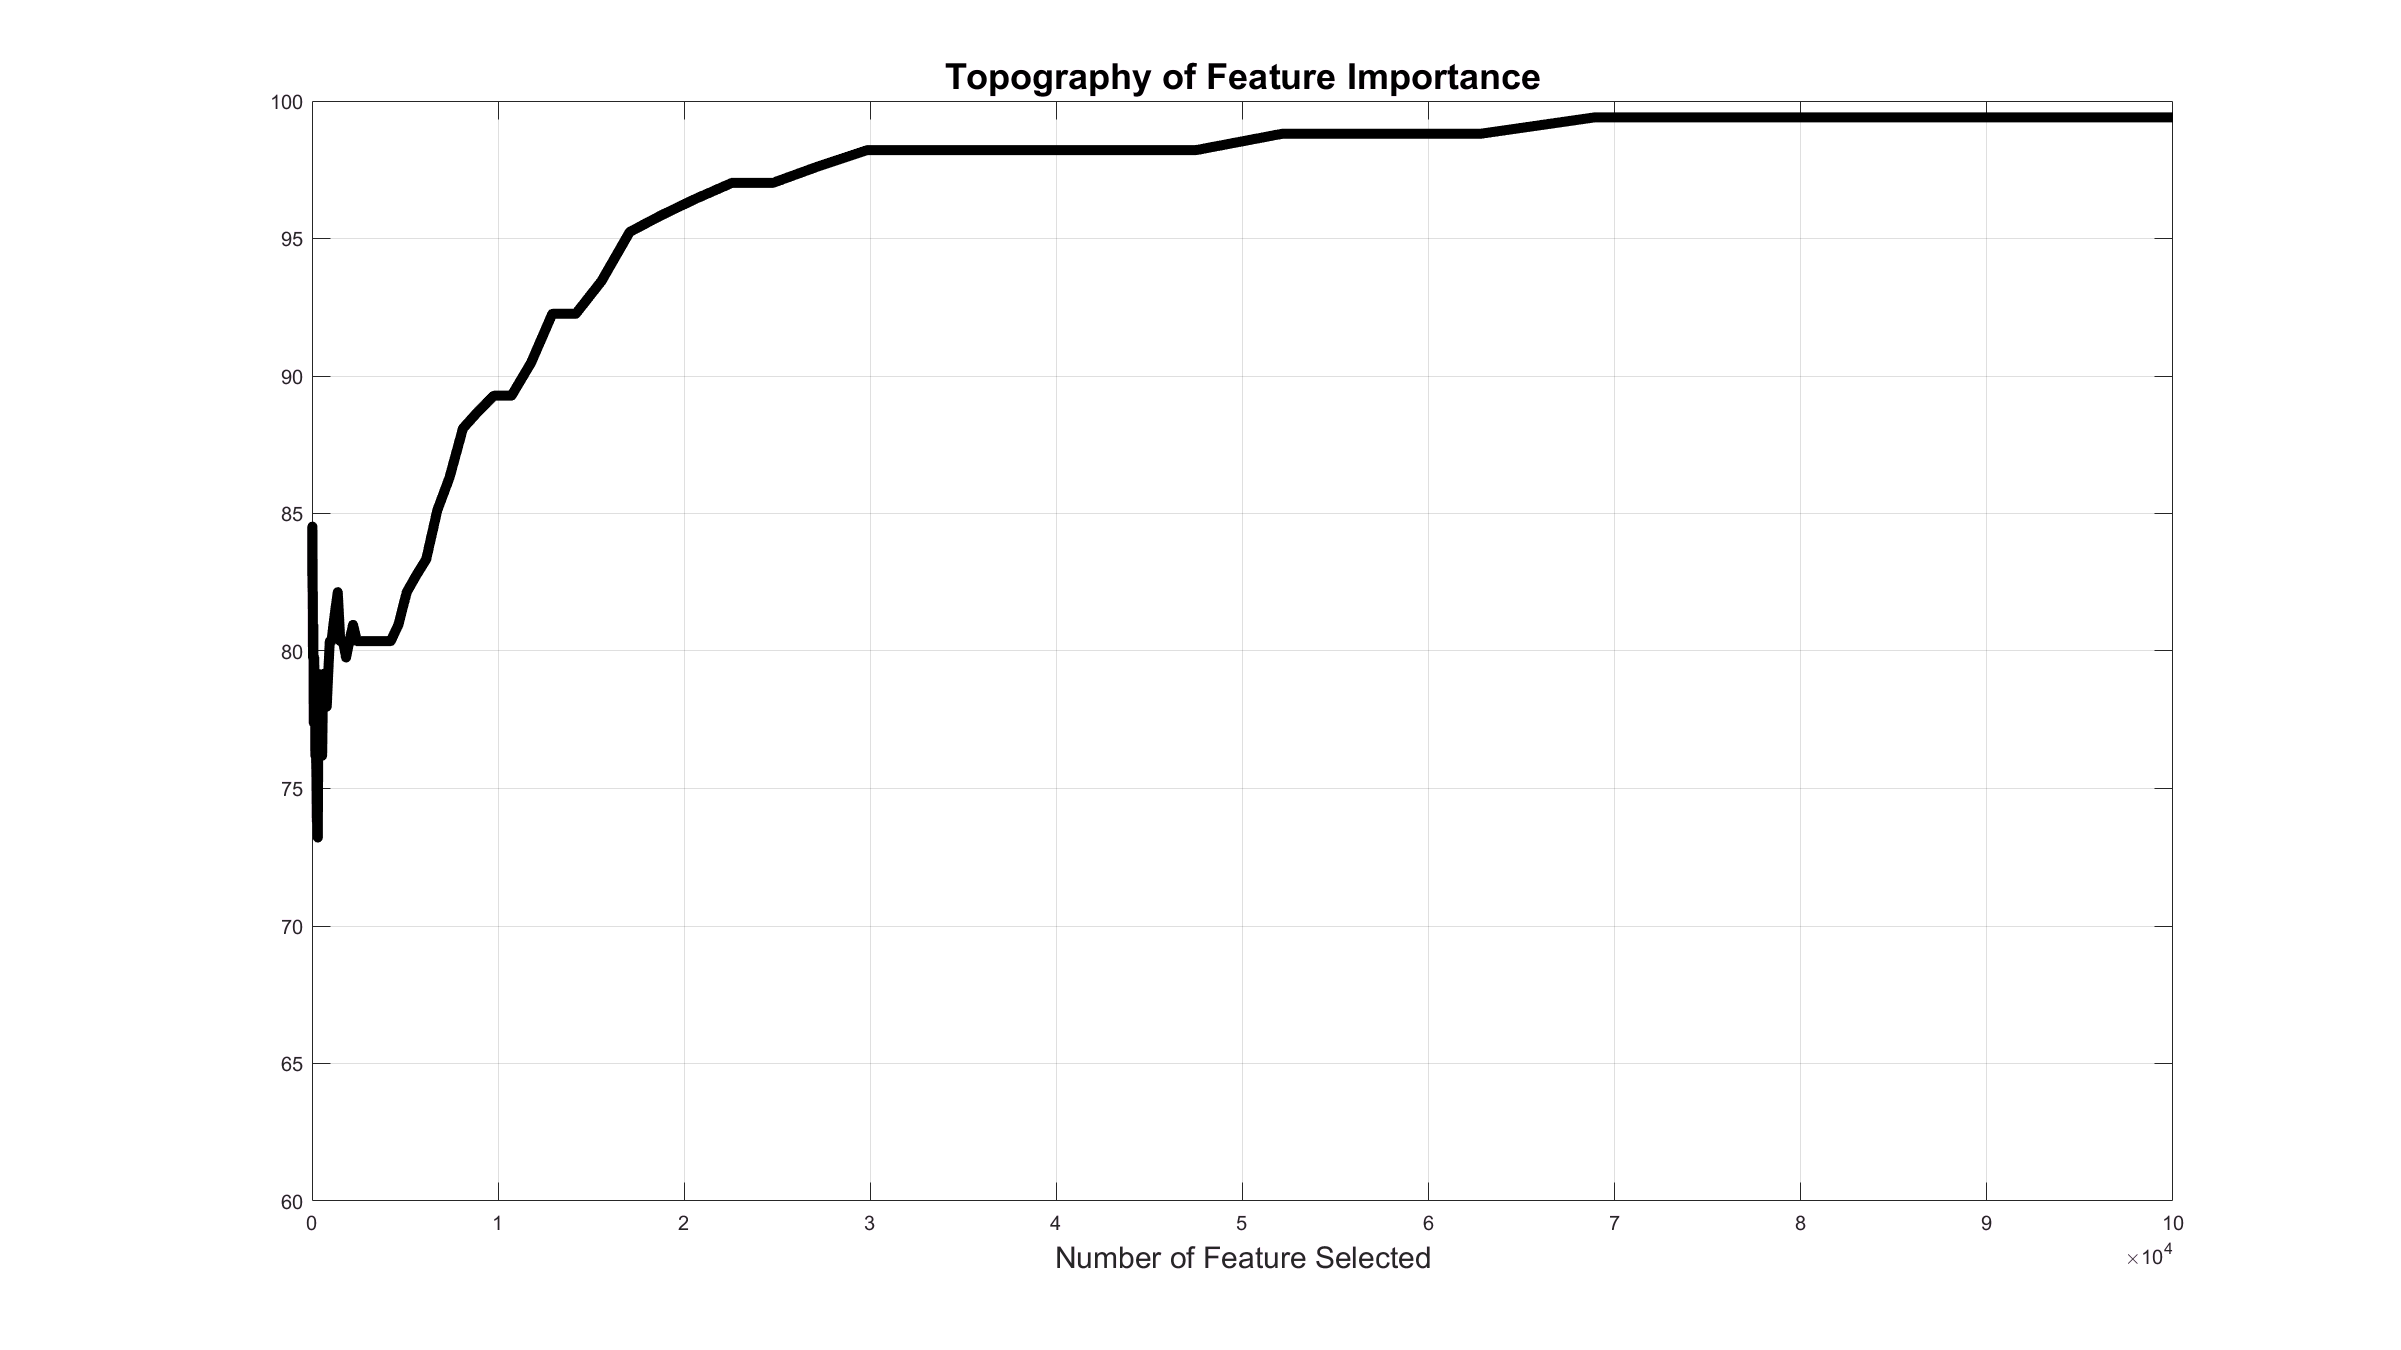


largeFigure(1, [1600 900]); clf; hold on; box on; grid on;
plot(FeatureLevel,ValidationAccuracy,'k','linewidth',5);
xlim([0 max(FeatureLevel)]); 
ylim([60 100]);
xlabel('Validation Accuracy','fontsize',15);
xlabel('Number of Feature Selected','fontsize',15);
title('Training Curve', 'fontsize', 18);

## Machine Learning - Feature Ranking compares to Physiology Pt.2: Visual Contour Map

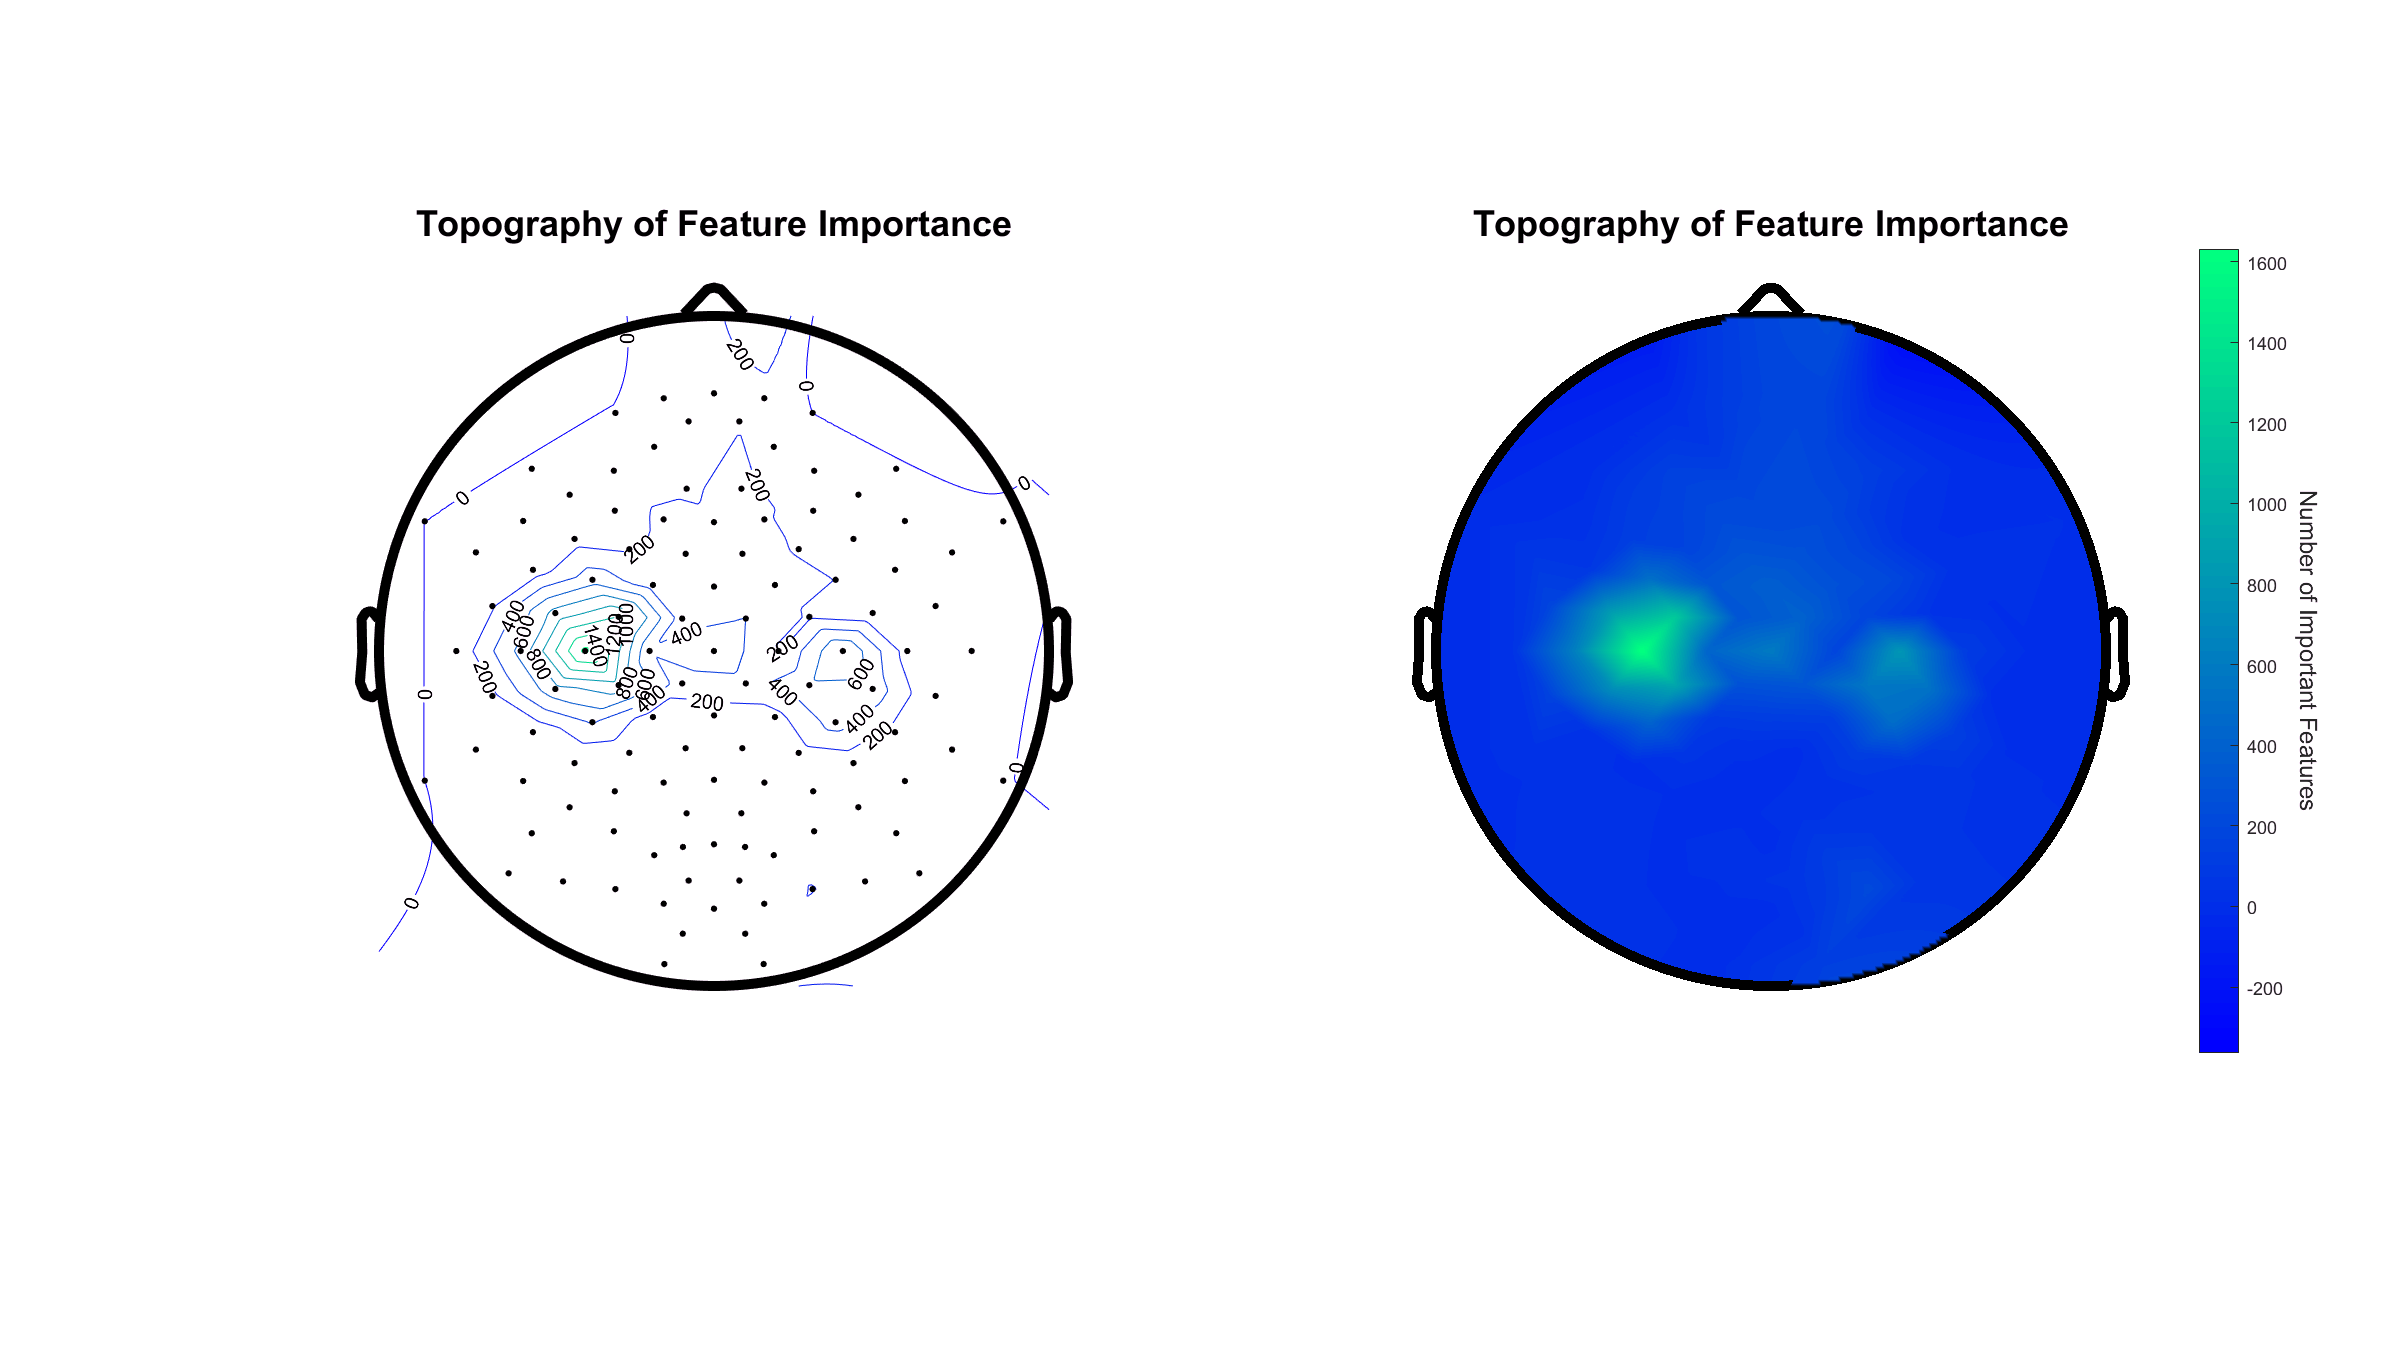

% Select first 20000 features
Significance = zeros(size(Significance));
Significance(FeatureRanking(1:20000)) = 1;
FeatureMap = reshape(Significance, [size(HandMovement,1),length(Frequency),length(SpectrumTime)]);

% Compute Topology for maximum separation
ImportantChannels = zeros(size(HandMovement,1),1);
for channel = 1:size(HandMovement,1)
    ImportantChannels(channel) = sum(sum(FeatureMap(channel,:,:)));
end

largeFigure(4, [1600 900]); clf; hold on; colormap winter;
subplot(1,2,1); cla; hold on;
F = scatteredInterpolant(nfo.xpos, nfo.ypos, ImportantChannels);
Vq = F(Xq,Yq);
contour(Xq,Yq,Vq,0:200:2000,'ShowText','on')
pbaspect(gca,[1,1,1]); axis off; axis([-1.2 1.2 -1.2 1.2]);
scatter3(nfo.xpos, nfo.ypos, ones(size(nfo.xpos))*100, 10, 'k', 'filled');
plot3(CircX, CircY, ones(size(CircY))*100, 'k', 'linewidth', 5);
plot(BrainOutline(6).XData-0.51,BrainOutline(6).YData,'k','linewidth',5)
plot(BrainOutline(7).XData+0.51,BrainOutline(7).YData,'k','linewidth',5)
plot(BrainOutline(8).XData,BrainOutline(8).YData+0.51,'k','linewidth',5)
title('Topography of Feature Importance', 'fontsize', 18);
subplot(1,2,2); cla; hold on;
surf(Xq, Yq, Vq, 'FaceColor','interp','AlphaData', Tranparency, 'FaceAlpha', 'interp'); shading interp;
pbaspect(gca,[1,1,1]); addColorbar('Number of Important Features'); axis off; axis([-1.2 1.2 -1.2 1.2]);
plot3(CircX, CircY, ones(size(CircY))*100, 'k', 'linewidth', 5);
plot(BrainOutline(6).XData-0.51,BrainOutline(6).YData,'k','linewidth',5)
plot(BrainOutline(7).XData+0.51,BrainOutline(7).YData,'k','linewidth',5)
plot(BrainOutline(8).XData,BrainOutline(8).YData+0.51,'k','linewidth',5)
title('Topography of Feature Importance', 'fontsize', 18);

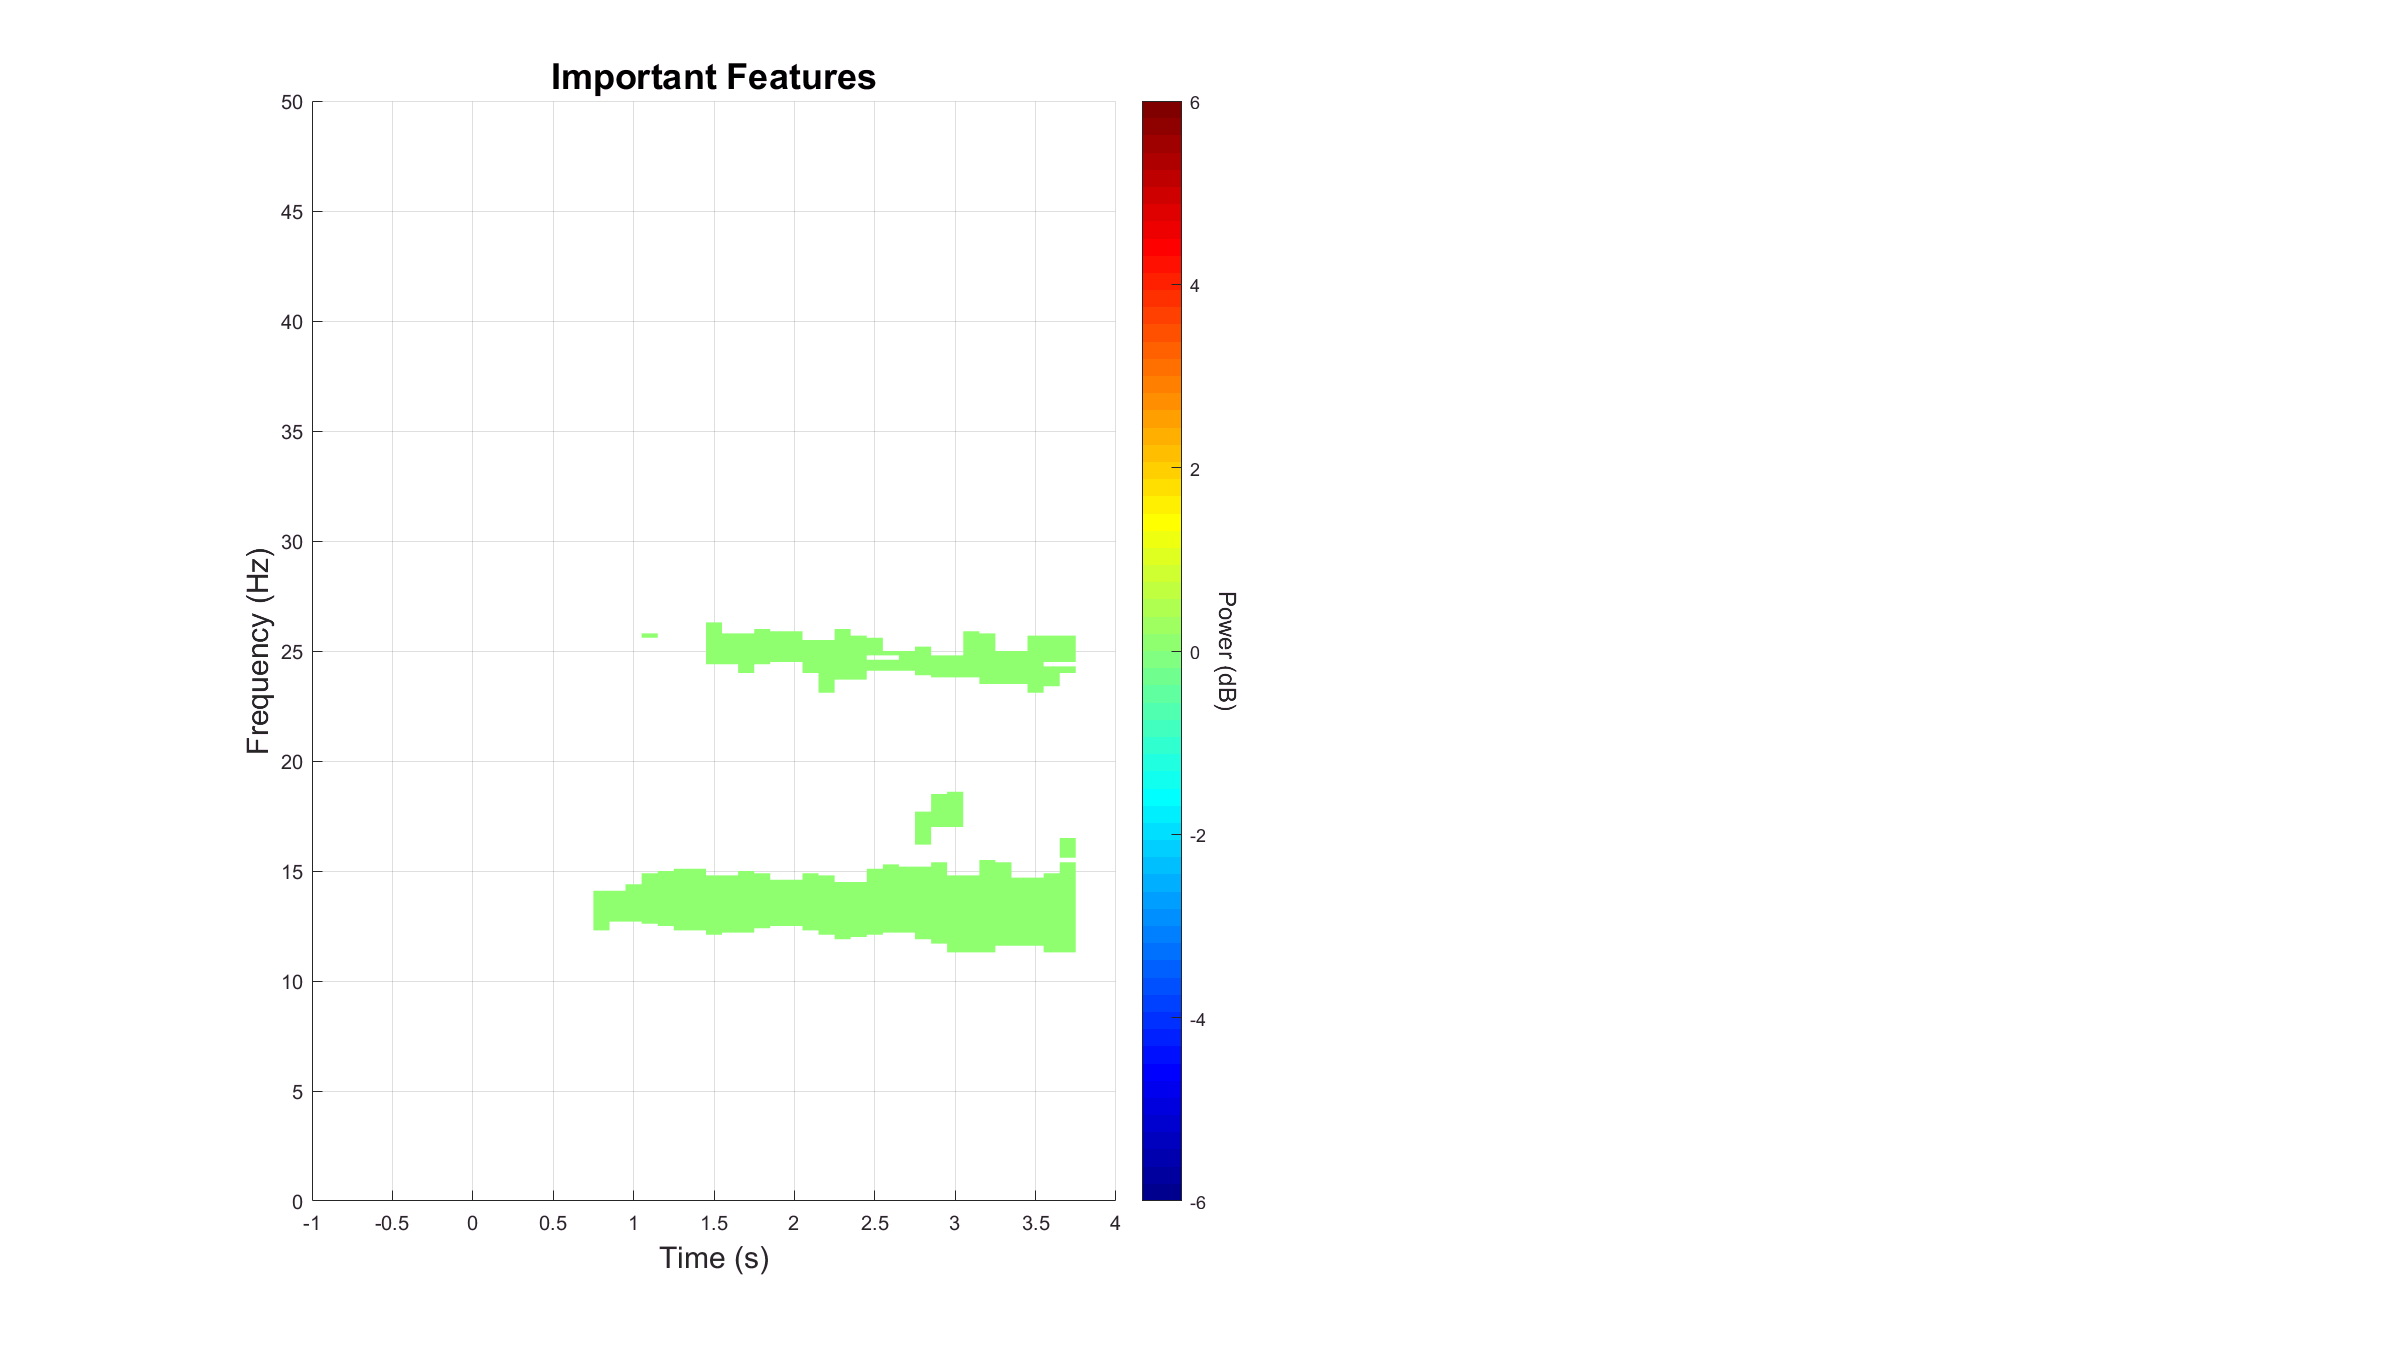


% Can we figure out what are the important features in the motor cortex?
largeFigure(5, [1600 900]); clf; colormap jet;
subplot(1,2,1); cla; box on; grid on;
surf(SpectrumTime+TimeRange(1), Frequency, 10*log10(squeeze(mean(mean(FeatureMap(52,:,:,:),4),1)))); view(2); shading interp;
axis([TimeRange 0 max(Frequency)]);
caxis([-6 6]);
addColorbar('Power (dB)');
xlabel('Time (s)', 'fontsize', 15);
ylabel('Frequency (Hz)', 'fontsize', 15);
title('Important Features','fontsize',18);

## Machine Learning - Final Testing

% This is the final test to our classifier
SelectedFeature = FeatureRanking(1:20000);
model = svmtrain(Label_train, Feature_train(:,SelectedFeature), '-s 0 -t 0');

*.*
optimization finished, #iter = 207
nu = 0.000017
obj = -0.001421, rho = -0.036396
nSV = 76, nBSV = 0
Total nSV = 76


[predicted_label, accuracy, decision_values] = svmpredict(Label_test, Feature_test(:,SelectedFeature), model);

Accuracy = 90.4762% (38/42) (classification)
